# Robust Maneuver Planning for Autonomous Vehicles

# Model Initialisation

The [VehicleFollowingInit](matlab:open('./VehicleFollowingInit.m')) script was created to specify and vary parameters for the simulation and to initialize the Simulink model. The script will be executed automatically when opening the [VehicleFollowing](matlab:open_system('VehicleFollowing.slx')) model.

# Kinematic Bicycle Model

The kinematic bicycle model can be used to simulate simplified car-like vehicle dynamics. The coordinate origin of this model is defined at the center of the bicycle's rear axle, which defines the body coordinate system $x_{b}$ and $y_{b}$. For the Simulink block, the used inputs that are the vehicle's velocity $v$ in $\frac{m}{s}$ and the steering angle $\psi$ in rad. The model outputs the state **[x, y, θ] **of the model, which is the vehicle's pose.

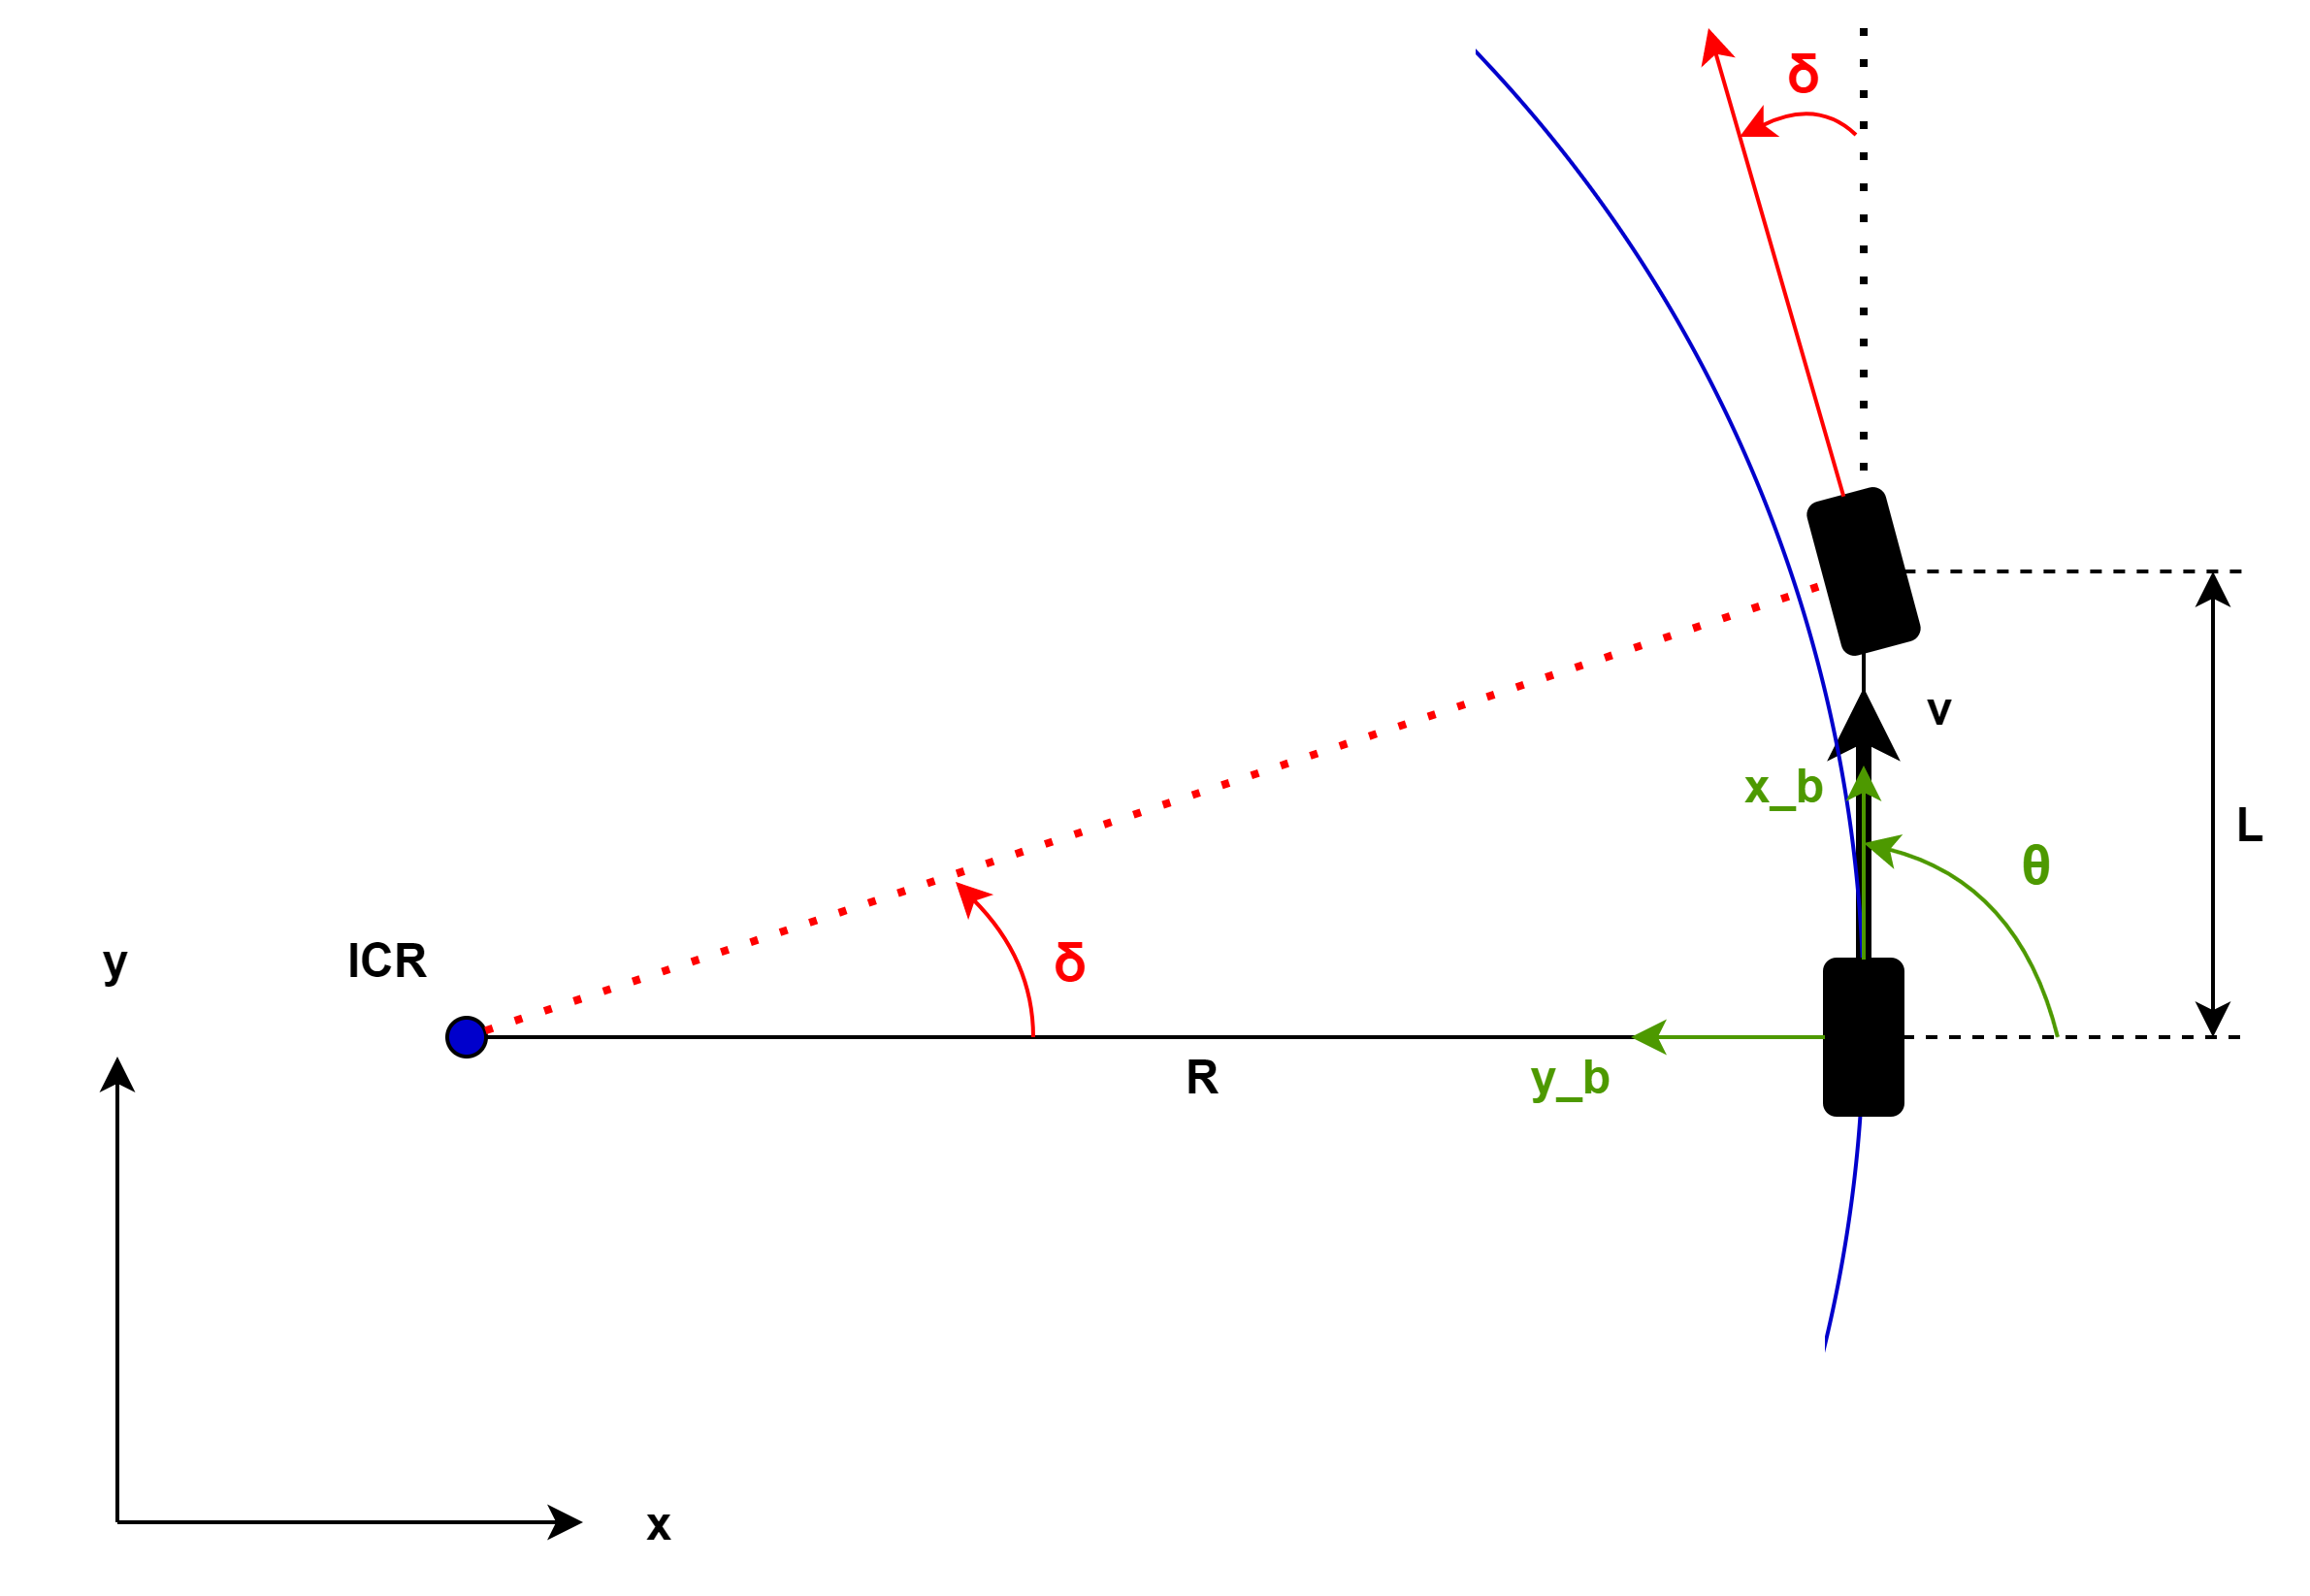

### Equations of motion

The origin of the body coordinate system moves along a circular path. The circle's center is the Instantaneous Center of Rotation (ICR) and has the radius $R$. Thus the eqations of motion are: 


$$\dot x = v \cos(\theta) \\
\dot y = v \sin(\theta) \\ 
\dot \theta = \frac{v}{L}tan(\delta)$$


The maximum steering angle $\delta_{max}$  and the wheel base $L$ limit the radius $R$ or respectively the curvature $\kappa$:


$$R_{min} = \frac{L}{tan(\delta_{max})} \\
\kappa_{max} = \frac{1}{R_{min}}  = \frac{tan(\delta_{max})}{L} \\ 
$$


### References

[https://www.mathworks.com/help/robotics/ref/bicyclekinematicmodel.html](https://www.mathworks.com/help/robotics/ref/bicyclekinematicmodel.html)

Corke, Peter I. *Robotics, Vision and Control: Fundamental Algorithms in MATLAB*. Springer, 2011.

# Constraints and Boundaries

For this model the following boundaries and constraints are considered:

## Road Boundaries

The road is bounded by its length and width, with $w_{lane} = 3.7$ being the lane width and $s$ and $d$ being the Frenet coordinates of the road:


$$s \in [0, \ s_{max}] \\
d \in [- \frac{1}{2}w_{lane},  \ \frac{3}{2}w_{lane}]$$


## Kinematic Constraints

The vehicles' kinematic is constrained by limiting the longitudinal velocity $\dot s$ and the longitudinal acceleration $\ddot s$. Only forward motion is allowed:


$$\dot s \in [0, \ \dot s_{max}] \\
\ddot s \in [\ddot s_{min}, \ \ddot s_{max}]$$


## Steering Constraints

In real systems the steering angle $\delta$ is usually limeted mechanically:


$$\delta \in [-\delta_{max}, \ \delta_{max}] \\
$$


# Vehicles

For now there are two vehicles to simulate, an ego vehicle and another leading vehicle. Other vehicles can easily be added to the model. 

## Ego Vehicle

The ego vehicle contains a decision unit to select a driving mode and to decide whether to change lane or not. Also there are the longitudinal and lateral motion components. Finally the vehicle generates its pose from the current velocity and steering angle using the kinematic bicycle model.

## Leading Vehicle

For now the other vehicle is only able to drive in the longitudinal $s$ direction. This vehicle does not use the kinematic bicycle model but instead uses a [simple vehicle dynamics model](https://www.mathworks.com/help/mpc/ug/adaptive-cruise-control-using-model-predictive-controller.html#d123e33810):

 
$$G = \frac{1}{s(0.5s + 1)}$$


# Coordinate Transformations

[Cartesian2Frenet](matlab:open('./Vehicle Functions\Helper Functions\Cartesian2Frenet.m')) [Frenet2Cartesian](matlab:open('./Vehicle Functions\Helper Functions\Frenet2Cartesian.m')) --> Documentation MOBATSim

# Longitudinal Control

--> MOBATSim

# Lateral Motion Control

In this Model one of two lateral controllers can be chosen. Using a Simulink Variant Subsystem block, either Pure Pursuit controller or Stanley controller can be selected. For Pure Pursuit, reference waypoints on the desired path need to be generated. The lateral Stanley controller on the other hand needs a reference pose on the path according to its front axle at every time step. Therefore the MATLAB Systems [PurePursuitWPGenerator.m](matlab:open('./Vehicle Functions\PurePursuitWPGenerator.m')) and [StanleyPoseGenerator.m](matlab:open('./Vehicle Functions\StanleyPoseGenerator.m')) were created. Both of them are a subclass of the [LocalTrajectoryPlanner.m](matlab:open('./Vehicle Functions\LocalTrajectoryPlanner.m')).

## Local Trajectory Planner

### Generate Reference Trajectory

The purpose of the [LocalTrajectoryPlanner.m](matlab:open('./Vehicle Functions\LocalTrajectoryPlanner.m')) is to generate a reference trajectory for the ego vehicle to either follow the lane or to execute a lane changing maneuver. Also functions to operate with the generated trajectory which are necessary for both Pure Pursuit and Lateral Stanley Control are provided.

The trajectory will be planned in the Frenet and Cartesian coordinate system for a previously defined time horizon ([planTrajectory](matlab:matlab.desktop.editor.openAndGoToLine(which('LocalTrajectoryPlanner.m'),  getFunctionLineNr('planTrajectory'));)):

The planned Frenet trajectory contains the waypoints for the future time horizon. The waypoints have the following format:

Normally, if there is no lane changing command, this function will just plan the reference trajecory to be on the right lane for the predefined time horizon ([calculateStraightTrajectory](matlab:matlab.desktop.editor.openAndGoToLine(which('LocalTrajectoryPlanner.m'),  getFunctionLineNr('calculateStraightTrajectory'));)). Therefore a prediction of the final $s$ value after this time will be made according to the ego velocity. The $d$ value will stay constant for this trajectory. At every time step, passed waypoints will be removed from the reference trajectory and new ones will be added, so that the length of the trajectory is always correct according to the time horizon and the sample time ([updateCurrentTrajectory](matlab:matlab.desktop.editor.openAndGoToLine(which('LocalTrajectoryPlanner.m'),  getFunctionLineNr('updateCurrentTrajectory'));)): 

If there is a command to change lane, the previously planned trajectory will be discarded and instead the lane changing trajectory will be used. To generate the lane changing trajectory, the minimum jerk trajectory either to the left or right lane for a previously defined maneuver time will be calculated ([calculateLaneChangingTrajectory](matlab:matlab.desktop.editor.openAndGoToLine(which('LocalTrajectoryPlanner.m'),  getFunctionLineNr('calculateLaneChangingTrajectory'));)). The lane calculated lane changing trajectory might be shorter or longer than the time horizon. To fit the reference length for the trajectory to plan, either a straight trajectory ([calculateStraightTrajectory](matlab:matlab.desktop.editor.openAndGoToLine(which('LocalTrajectoryPlanner.m'),  getFunctionLineNr('calculateStraightTrajectory'));)) must be added if the maneuver time is shorter than the time horizon, or a resiudal lane changing trajectory must be kept and added to the planned trajectory later in case it is longer ([divideLaneChangingTrajectory](matlab:matlab.desktop.editor.openAndGoToLine(which('LocalTrajectoryPlanner.m'),  getFunctionLineNr('divideLaneChangingTrajectory'));)) ([calculateTrajectoryToAdd](matlab:matlab.desktop.editor.openAndGoToLine(which('LocalTrajectoryPlanner.m'),  getFunctionLineNr('calculateTrajectoryToAdd'));)).

The generated reference trajectory will be transformed from Frenet to Cartesian coordinate system ([getCurrentTrajectoryCartesian](matlab:matlab.desktop.editor.openAndGoToLine(which('LocalTrajectoryPlanner.m'),  getFunctionLineNr('getCurrentTrajectoryCartesian'));)). The waypoints have the following format:

Furthermore, according to the current $s$ value, a number of next waypoints in the planned Frenet trajectory can be returned ([getNextFrenetTrajectoryWaypoints](matlab:matlab.desktop.editor.openAndGoToLine(which('LocalTrajectoryPlanner.m'),  getFunctionLineNr('getNextFrenetTrajectoryWaypoints'));)).

The error between the predicted $s$ and $d$ value of the planned trajectory and the actual values after the time according to the predifined time horizon has passed, can be tracked ([calculateTrajectoryError](matlab:matlab.desktop.editor.openAndGoToLine(which('LocalTrajectoryPlanner.m'),  getFunctionLineNr('calculateTrajectoryError'));)). The error will be computed every few seconds. This period of time will be a specified fraction of the time horizon. If the error exceeds a certain value, this function can be used to generate a command for replanning the trajectory.

## Pure Pursuit Controller

Pure Pursuit is an algorithm that is used for path tracking. It takes the vehicle's current pose **[x, y, θ] **and the next waypoints' coordinates **[x, y]** as an input. The figure shows the desired path defined by different waypoints (WPs) and the vehicle's current position and orientation. 

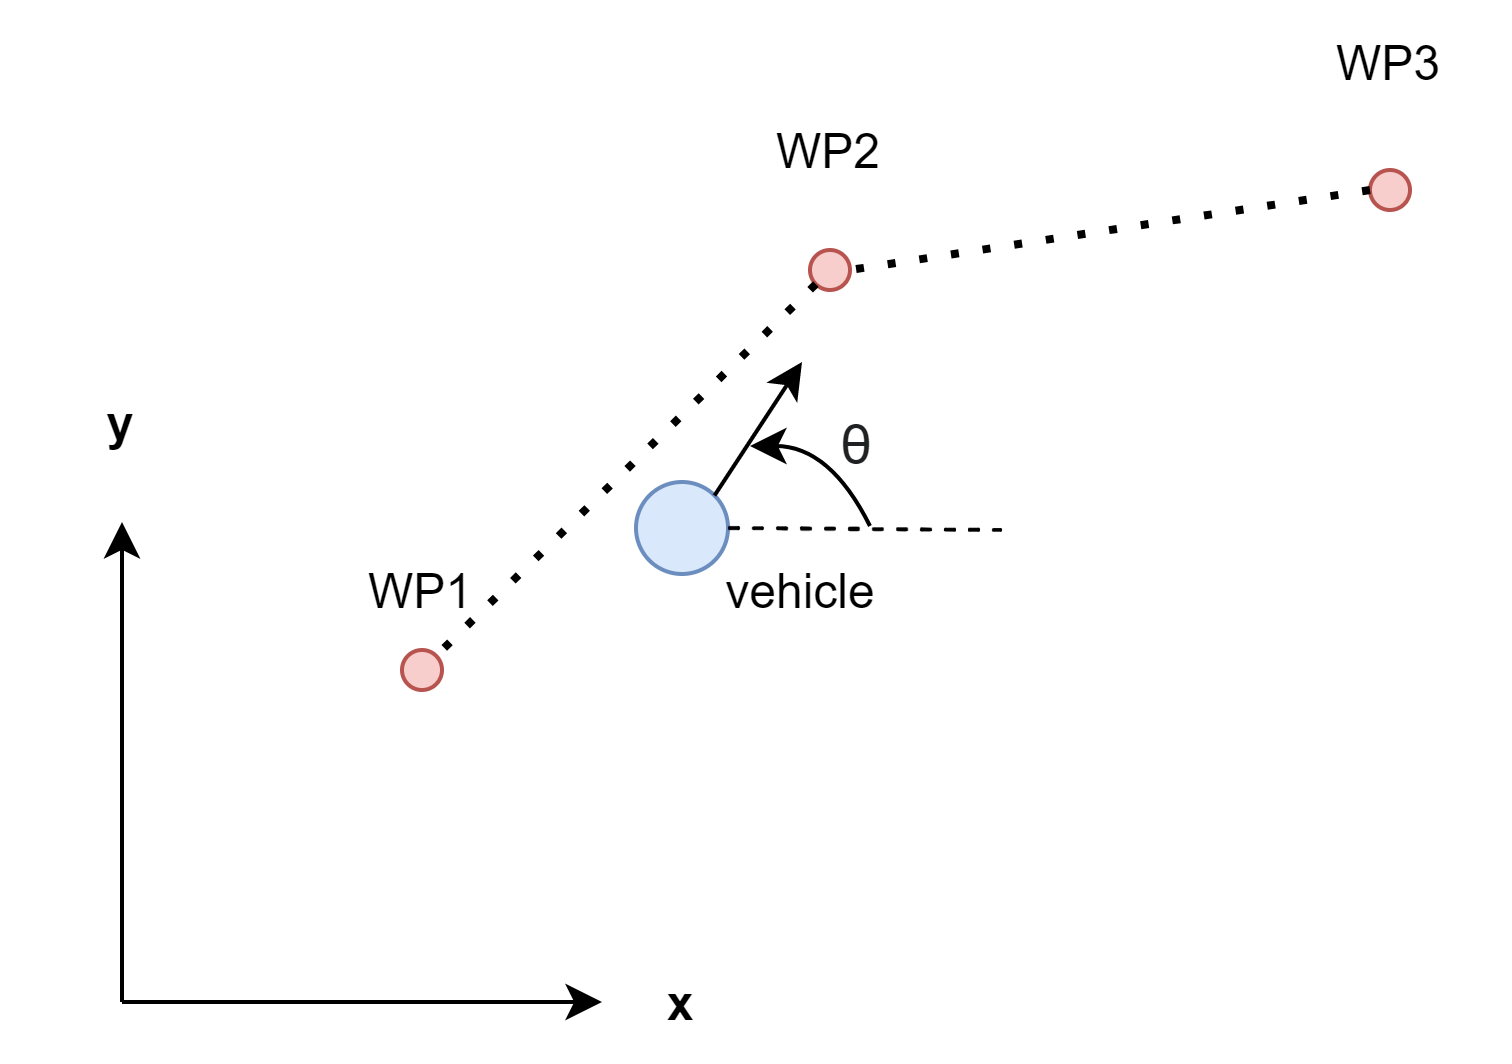

### Look Ahead Distance

To tune this algorithm, the look ahead distance $l_d$ can be adjusted. It states how far ahead on the path the vehicle should look from its current position. A small look ahead distance results in quickly moving towards the path but thus overshoots are possible. A large look ahead distance on the other hand avoids these overshoots but lets the vehicle move slower towards the path which may result in larger curvatures in corners.

### Steering Angle

The output that is used to compute the steering angle $\delta$ command for the vehicle kinematic bicycle model, is the target direction $\alpha$:

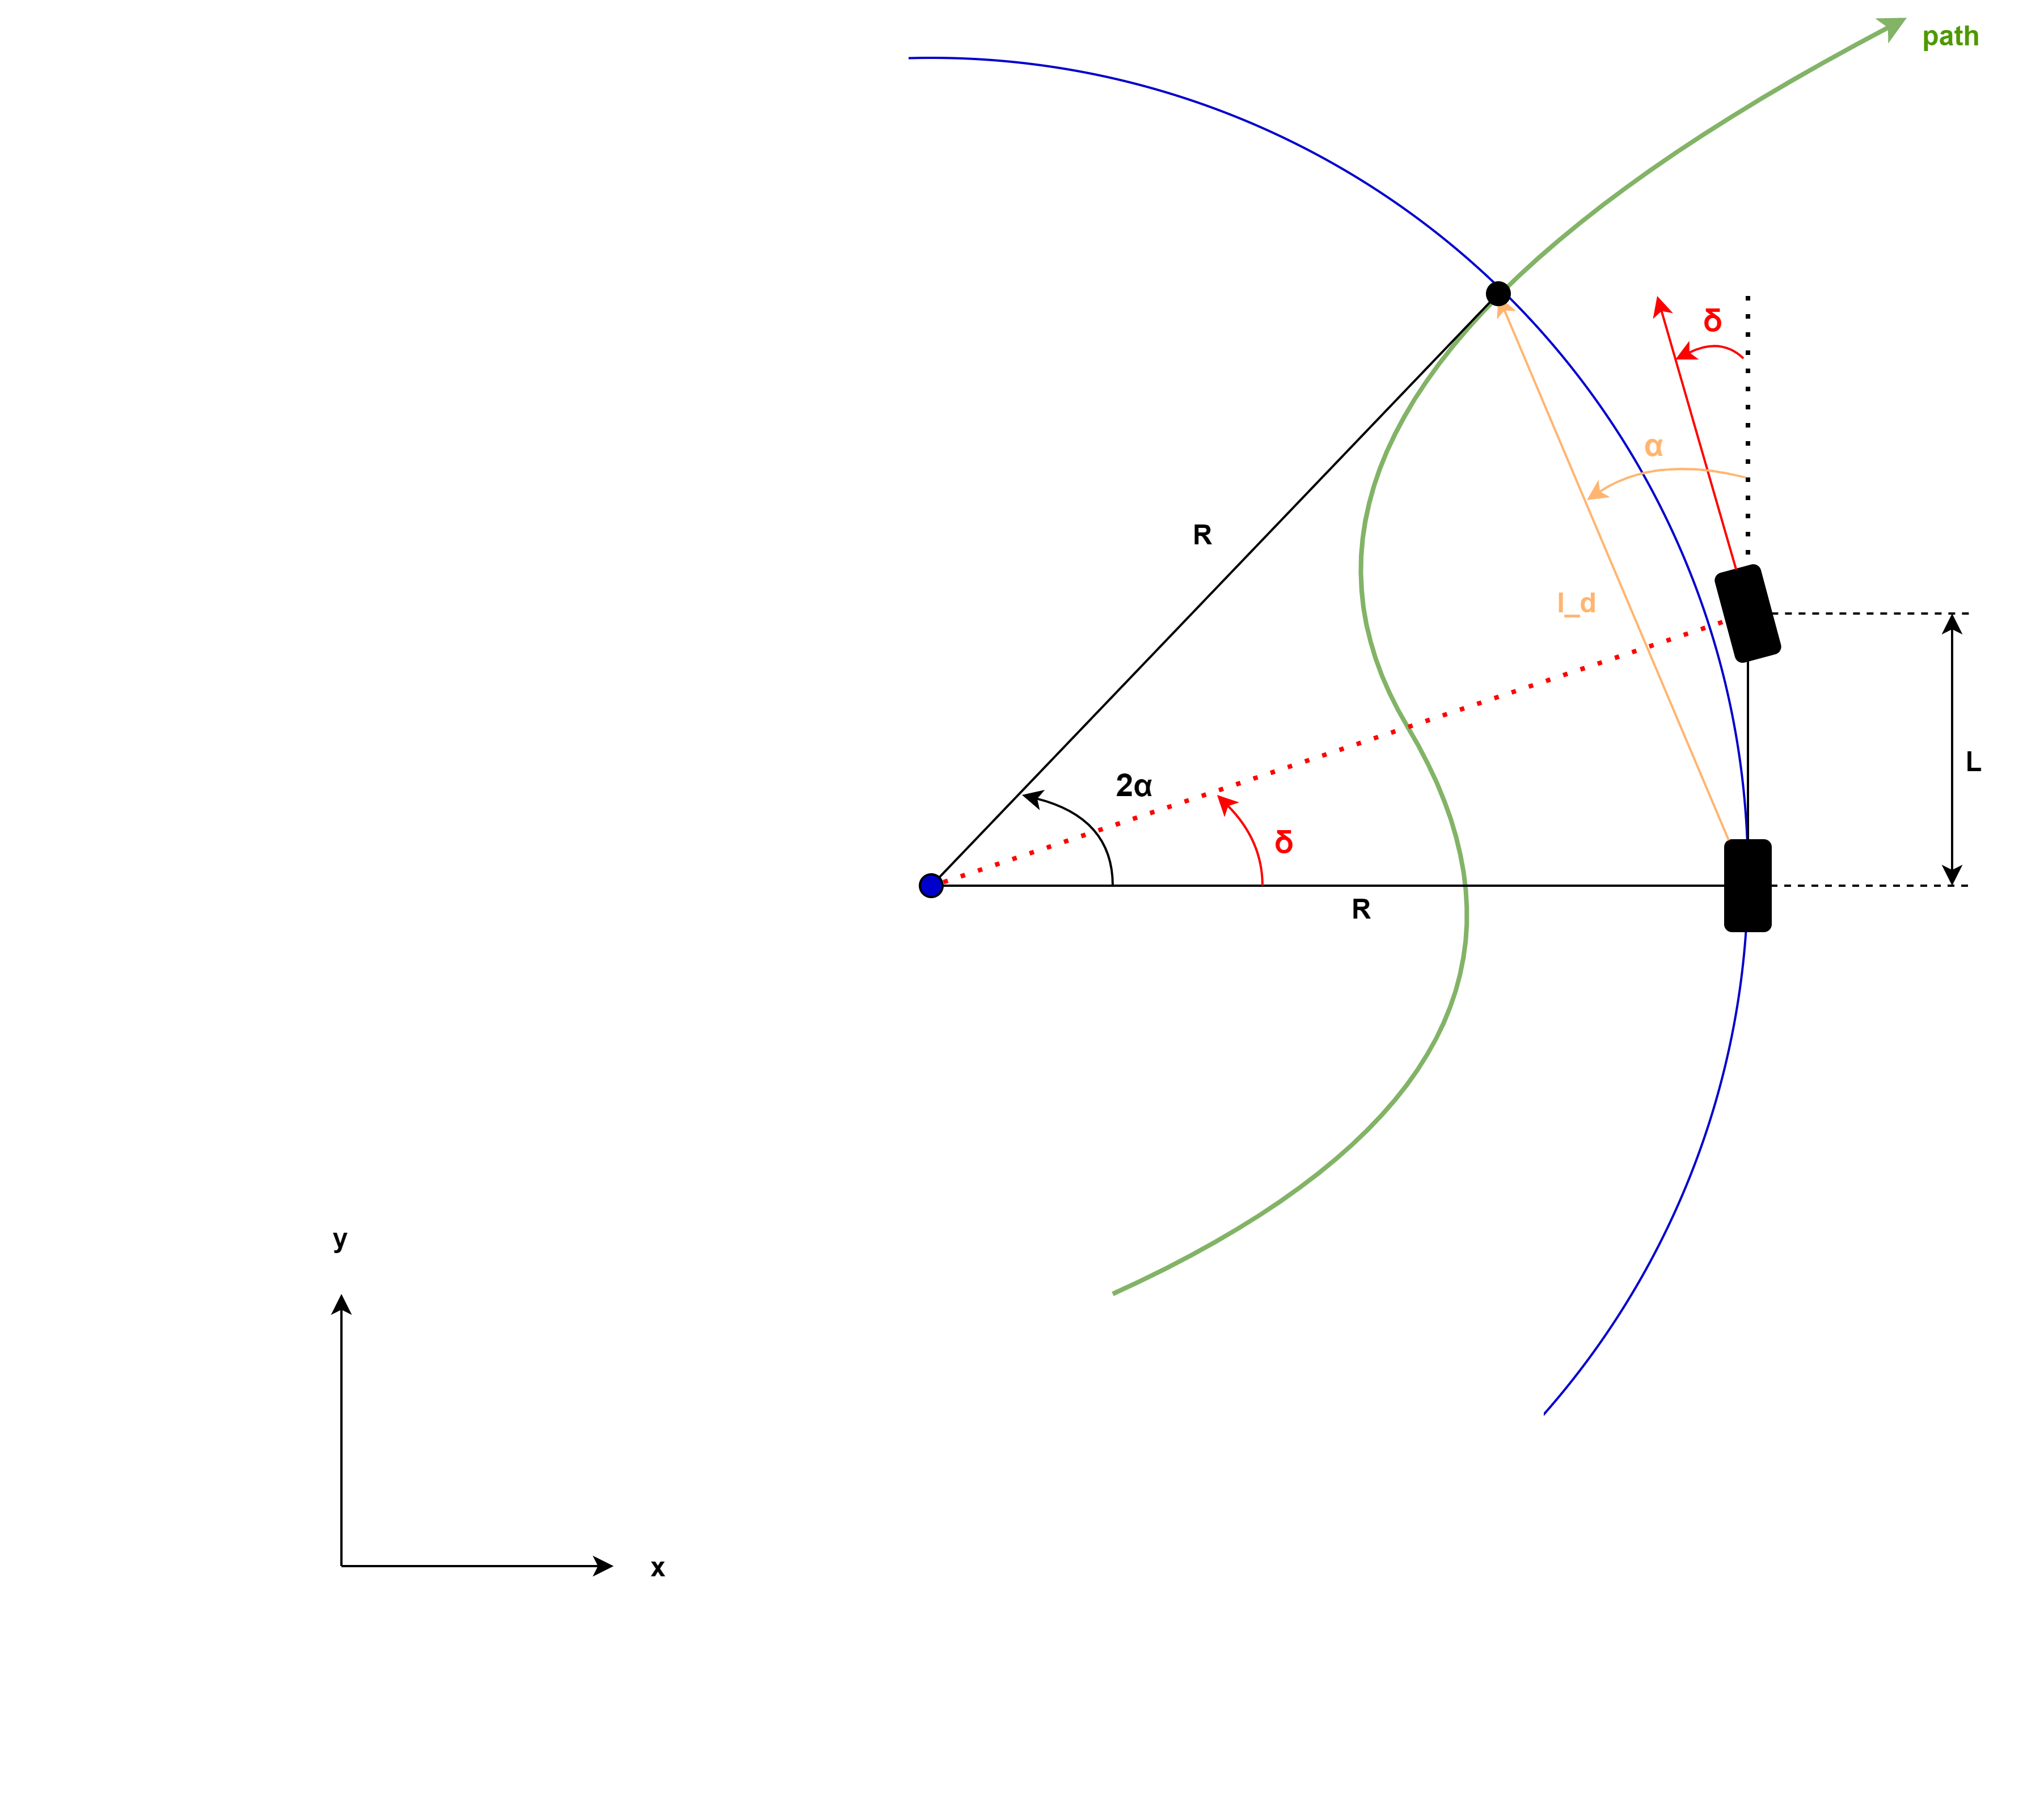

The steering angle $\delta$ can be calculated as follows:


$$\delta = arctan(\frac{L}{R})$$


From the law of sines, $R$ can be obtained:

 
$$\frac{l_d}{sin(2\alpha)} = \frac{R}{sin(\frac{\pi}{2} - \alpha)}$$



$$\frac{l_d}{2\sin(\alpha)\cos(\alpha)} = \frac{R}{cos(\alpha)}$$



$$R = \frac{l_d}{2\sin(\alpha)}$$


This results in:


$$\delta = arctan\left( \frac{2\ L\ sin(\alpha)}{l_{d}} \right)$$


### References

[https://www.mathworks.com/help/robotics/ug/pure-pursuit-controller.html](https://www.mathworks.com/help/robotics/ug/pure-pursuit-controller.html)

[https://www.youtube.com/watch?v=qYR7mmcwT2w](https://www.youtube.com/watch?v=qYR7mmcwT2w)

Coulter, R. *Implementation of the Pure Pursuit Path Tracking Algorithm*. Carnegie Mellon University, Pittsburgh, Pennsylvania, Jan 1990.

## Pure Pursuit Waypoint Generator

To provide the reference waypoints for the Pure Pursuit algorithm, the [PurePursuitWPGenerator.m](matlab:open('./Vehicle Functions\PurePursuitWPGenerator.m')) is used:

First of all, the current pose is transformed to Frenet coordinates. Then, at every time step, the trajectory will be planned ([planTrajectory](matlab:matlab.desktop.editor.openAndGoToLine(which('LocalTrajectoryPlanner.m'),  getFunctionLineNr('planTrajectory'));)) for the specified time horizon. Finally the next waypoints in the trajectory ([getNextFrenetTrajectoryWaypoints](matlab:matlab.desktop.editor.openAndGoToLine(which('LocalTrajectoryPlanner.m'),  getFunctionLineNr('getNextFrenetTrajectoryWaypoints'));)) will be transformed back to Cartesian coordinates to provide the input for the Pure Pursuit algorithm.

## Lateral Stanley Controller

The Lateral Stanley Controller can also be used for path tracking. Using the kinematic bicycle model, the inputs are:

- The reference pose **[x_ref, y_ref, θ_ref]**: While only considering forward motion, the reference location x_ref, y_ref is the point on the path which is closest to the center of the vehicle's front axle. The reference angle θ_ref is the orientation at this reference location on the path in degrees.

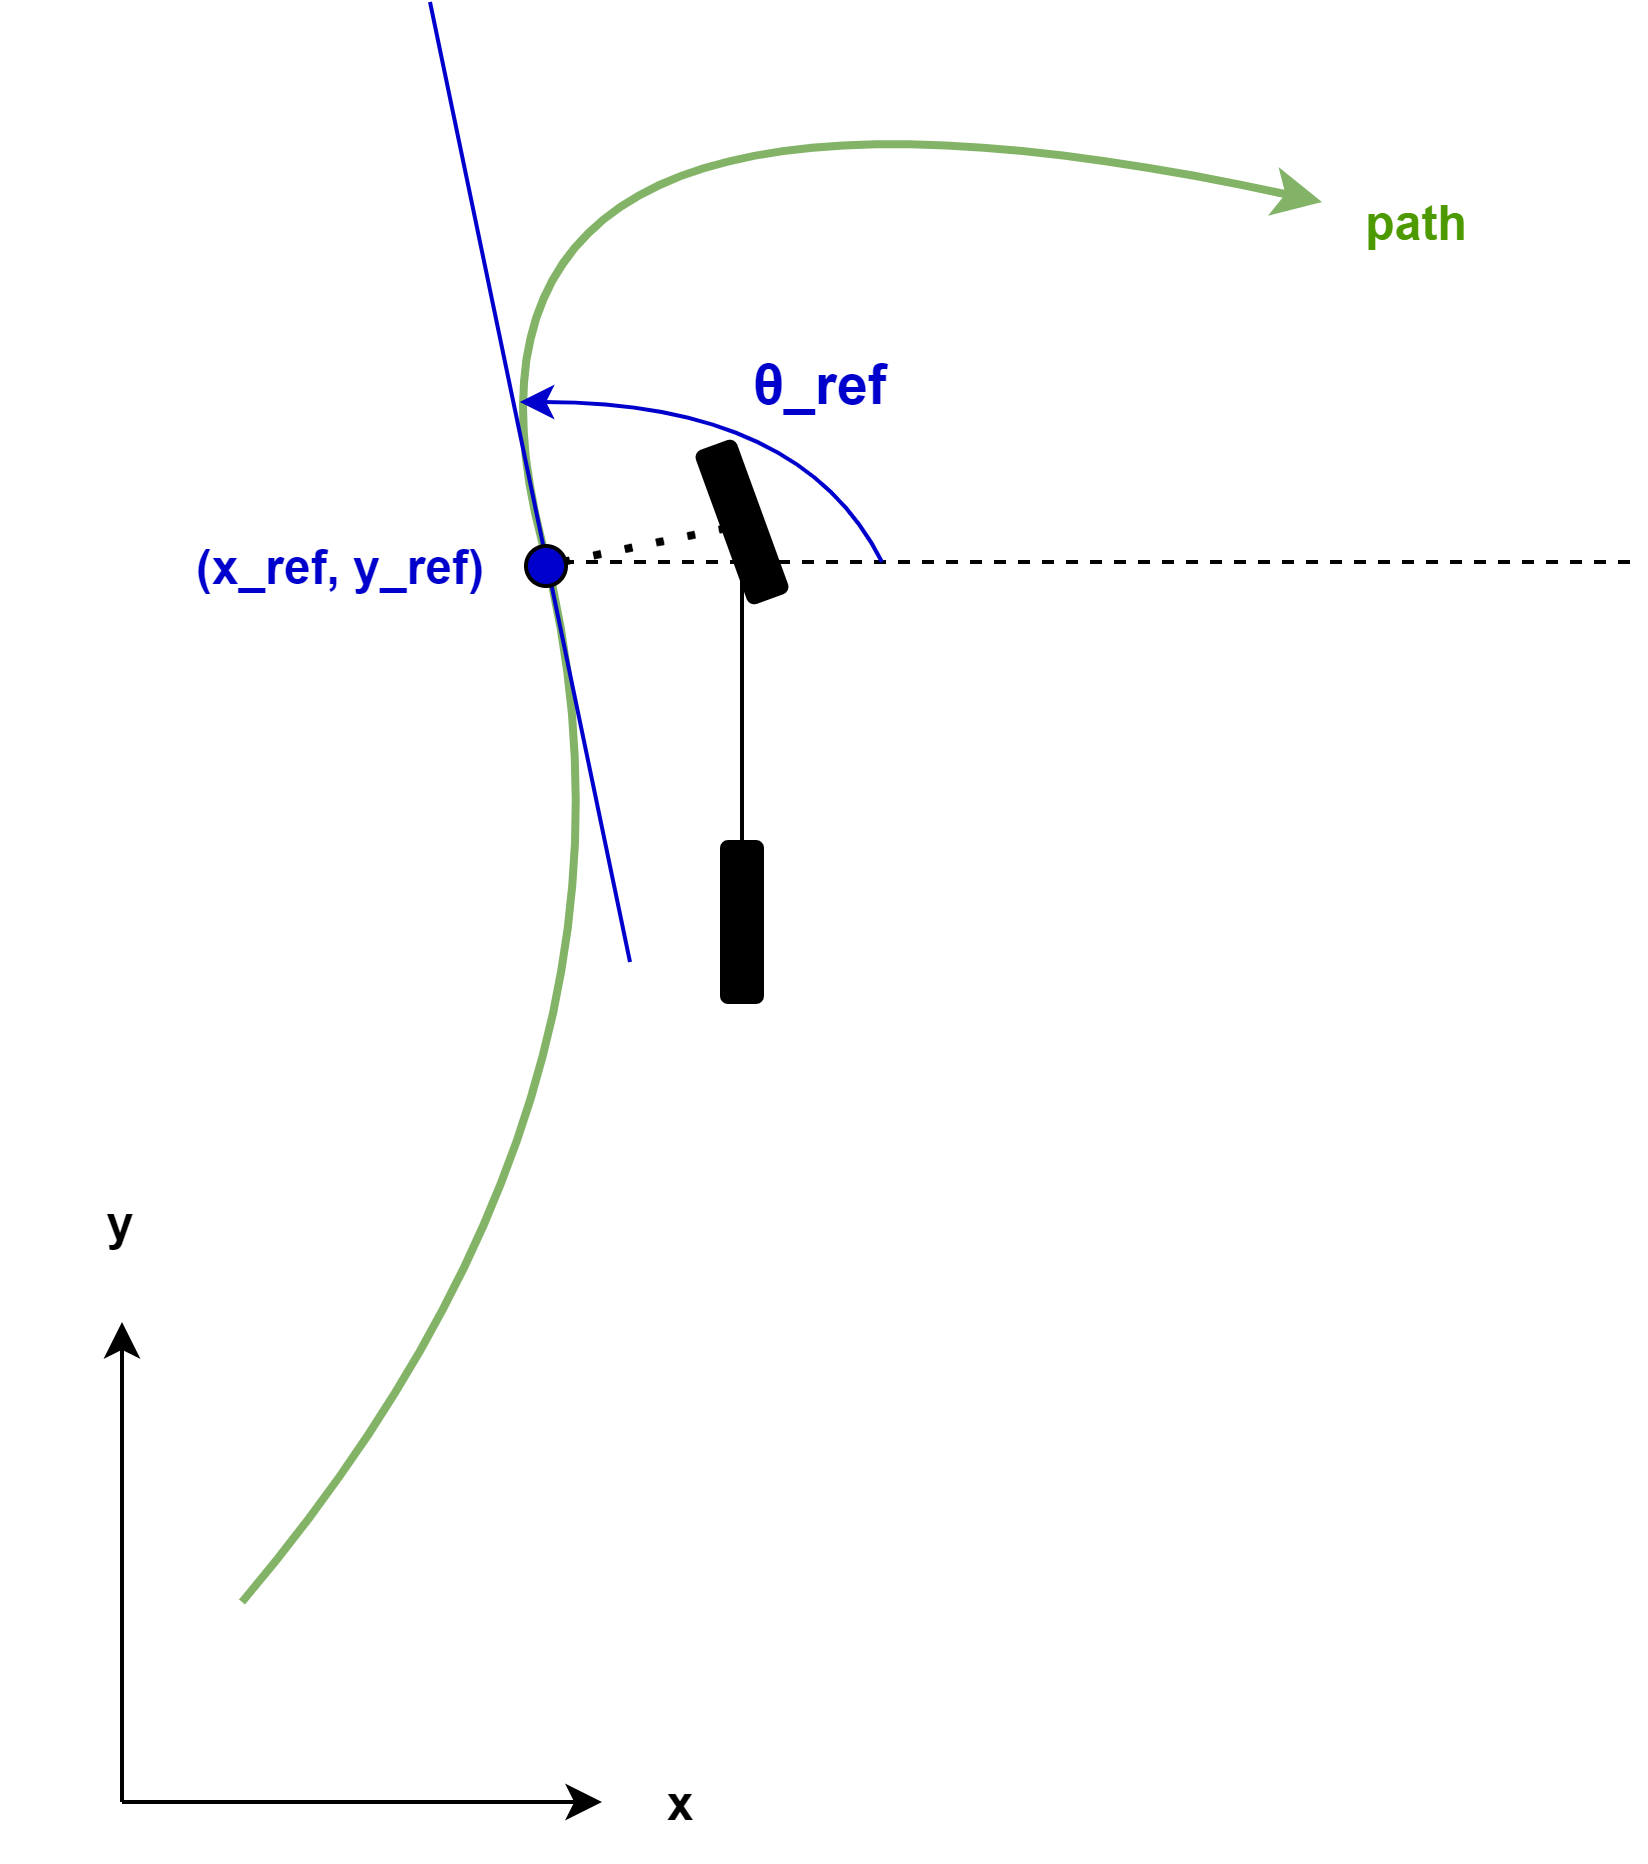

- The current pose **[x, y, θ]**: This is the current pose of the vehicle according to the center of the vehicle's rear axle. The current orientation θ must be in degrees.

- The current velocity of the vehicle in $\frac{m}{s}$

- The vehicle's direction: The constant 1 is used for forward motion.

The controller outputs the steering angle $\delta$ in degrees. Therefore, to use this angle as the input for the bicycle kinematic model, a transformation to radians is necessary.

### Position Gain Of Forward Motion

To tune the controller, the position gain can be adjusted. For forward motion, only the position gain for forward motion needs to be considered. The higher this value is, the more the position error will affect steering angle adjustmens.

### Steering Control Law

The steering control law considers the cross track error $e(t)$, the vehicles speed $v(t)$ and the vehicle's heading $\psi (t)$ with respect to the closest trajectory segment (see figure below). The reference point is the center of the vehicle's front axle. For the kinematic bicycle model, the steering angle $\delta(t)$ is calculated as follows, with $k$ being the gain and $\delta_{max}$ being the maximum steering angle:


$$\delta(t) =
    \begin{cases}
      \psi(t) + arctan(\frac{k\ e(t)}{v(t)}) & \text{if } |\psi(t) + arctan(\frac{k\ e(t)}{v(t)})| < \delta_{max} \\
      \delta_{max} & \text{if }  \psi(t) + arctan(\frac{k\ e(t)}{v(t)}) \geq \delta_{max} \\
      -\delta_{max}  &  \text{if } \psi(t) + arctan(\frac{k\ e(t)}{v(t)}) \leq \delta_{max} \\
    \end{cases} $$


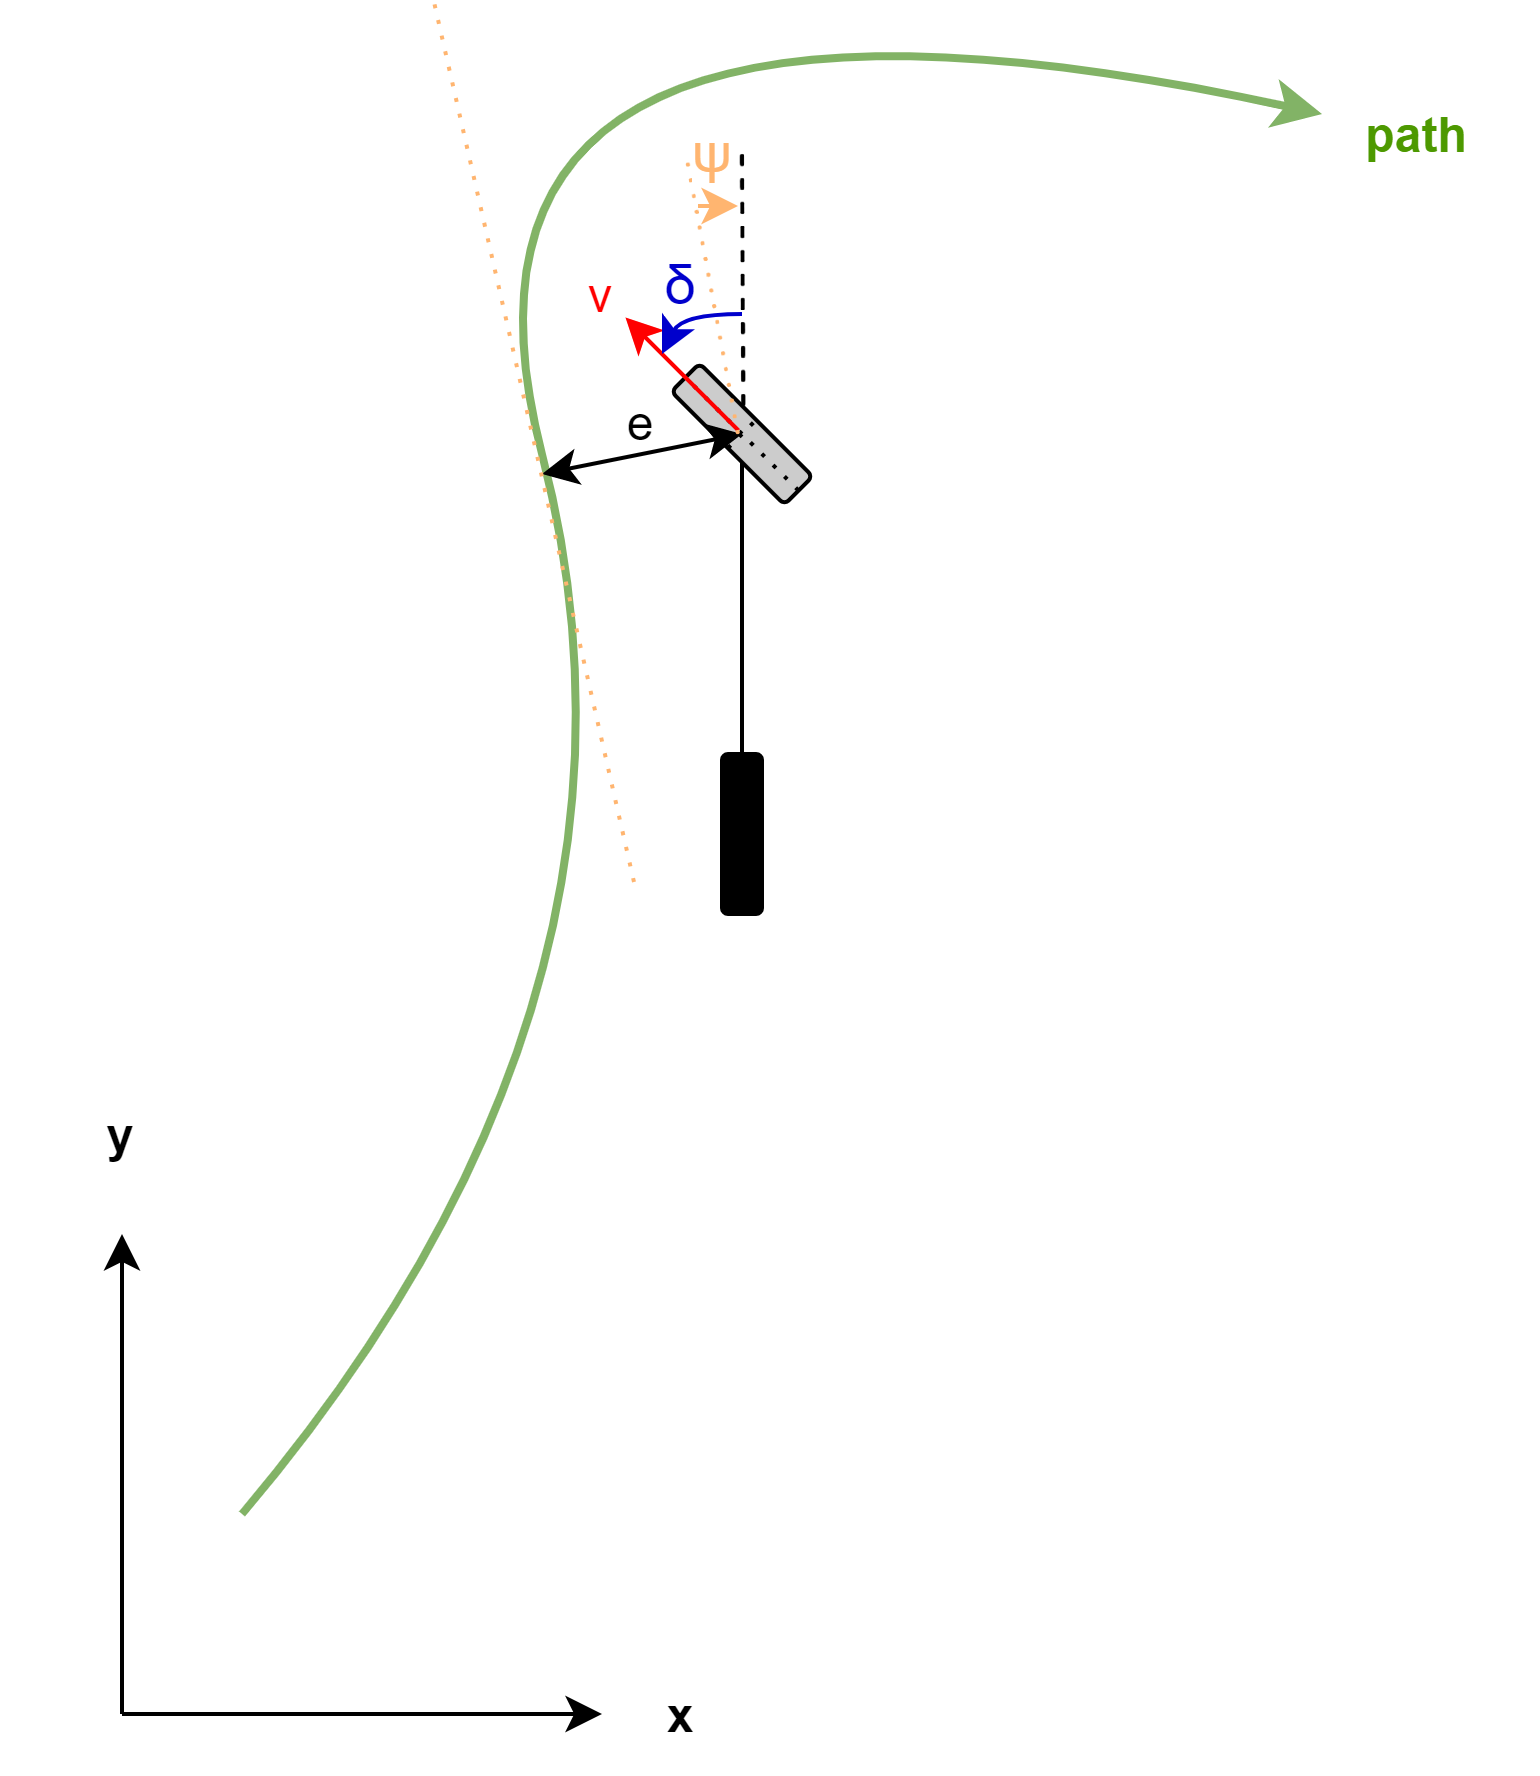

### Error Minimisation

To reduce the cross lateral error $\Delta d = d_{actual} - d_{reference}}$ for tracking the desired path, the [Global Optimization Toolbox](https://www.mathworks.com/products/global-optimization.html) with a [Genetic Algorithm](https://www.mathworks.com/discovery/genetic-algorithm.html) is used. Therefore the functions [error_d_optimisation](matlab:open('./Vehicle Functions\Helper Functions\error_d_optimisation.m')) and [error_d](matlab:open('./Vehicle Functions\Helper Functions\error_d.m')) are created, to find the optimal value for the position gain of forward motion.

### References

[https://www.mathworks.com/help/driving/ref/lateralcontrollerstanley.html](https://www.mathworks.com/help/driving/ref/lateralcontrollerstanley.html)

[https://www.youtube.com/watch?v=9Y7kVIJs_JI](https://www.youtube.com/watch?v=9Y7kVIJs_JI)

Hoffmann, Gabriel M., Claire J. Tomlin, Michael Montemerlo, and Sebastian Thrun. "Autonomous Automobile Trajectory Tracking for Off-Road Driving: Controller Design, Experimental Validation and Racing." *American Control Conference*. 2007, pp. 2296–2301. doi:10.1109/ACC.2007.4282788

## Stanley Pose Generator

To provide the reference pose for the Stanley controller, the [StanleyPoseGenerator.m](matlab:open('./Vehicle Functions\StanleyPoseGenerator.m')) is used:

First of all, the current posed is transformed to Frenet coordinates. Then, at every time step, the trajectory will be planned ([planTrajectory](matlab:matlab.desktop.editor.openAndGoToLine(which('LocalTrajectoryPlanner.m'),  getFunctionLineNr('planTrajectory'));)) for the specified time horizon. A reference pose according to the center of the ego vehicle's front axle ([getVehicleFrontAxleCenterPoint](matlab:open('./Vehicle Functions\Helper Functions\getVehicleFrontAxleCenterPoint.m'))) must be generated ([getReferencePoseStanley](matlab:matlab.desktop.editor.openAndGoToLine(which('StanleyPoseGenerator.m'),  getFunctionLineNr('getReferencePoseStanley'));)):

It is necessary to find the waypoint on the trajectory which is closest to the center of the vehicle's front axle ([getClosestPointOnTrajectory](matlab:matlab.desktop.editor.openAndGoToLine(which('StanleyPoseGenerator.m'),  getFunctionLineNr('getClosestPointOnTrajectory'));)). This will return the reference position in Cartesian coordinates. The reference orientation was already generated, when planning the trajectory.

# Longitudinal Reachability Analysis

For the leading vehicle a [longitudinal reachability analysis](matlab:open('./Vehicle Functions\LongitudinalReachability.m')) is done to estimate its future position $s$ and velocity $v$ when applying the maximum or minimum possible longitudinal acceleration $a_{max}$ or $a_{min}$ for a specified time horizon. The future states at time step $k+1$ can be calculated by the following expression with $T_{s}$ being the sample time:


$$$\left[ \begin{array}{r}
s(k+1) \\ 
v(k+1)\\
\end{array}\right]$

=

$\left[ \begin{array}{rr}
1 & (k+1)T_{s}  \\ 
0 & 1  \\
\end{array}\right]$

$\left[ \begin{array}{r}
s(0) \\ 
v(0) \\ 
\end{array}\right]$

+

$\left[ \begin{array}{r}
\frac{T_{s}^2}{2}  \sum\nolimits_{j=0}^k\ (2k + 1 - 2j)a_{j} \\
T_{s} \sum\nolimits_{j=0}^k\ a_{j} \\
\end{array}\right]$$$


With the maximum or minimum acceleration being constant, this simplifies to:


$$$\left[ \begin{array}{r}
s(k+1) \\ 
v(k+1)\\
\end{array}\right]$

=

$\left[ \begin{array}{rr}
1 & (k+1)T_{s}  \\ 
0 & 1  \\
\end{array}\right]$

$\left[ \begin{array}{r}
s(0) \\ 
v(0) \\ 
\end{array}\right]$

+

$\left[ \begin{array}{r}
\frac{T_{s}^2}{2} \ a \sum\nolimits_{j=0}^k\ (2j + 1) \\
 \ T_{s}  (k + 1)   a   \\
\end{array}\right]$$$


# Lateral Reachability Analysis

By using the longitudinal reachability analysis with a constant acceleration $a$, the longitudinal distance $\Delta s = s(k+1) - s(0)$, which is covered in a specified time horizon $T_{h} = (k+1)T_{s}$, can be calculated. When assuming that the wheels roll without slipping sideways, $\Delta s$ should be equal to the arc length for different constant steering angles $\delta \in [-\delta_{max}, \ \delta_{max}]$. Thus, an area limiting the possible future positions for the [reachability analysis](matlab:open('./Vehicle Functions\ReachabilityAnalysis.m')) can be predicted:

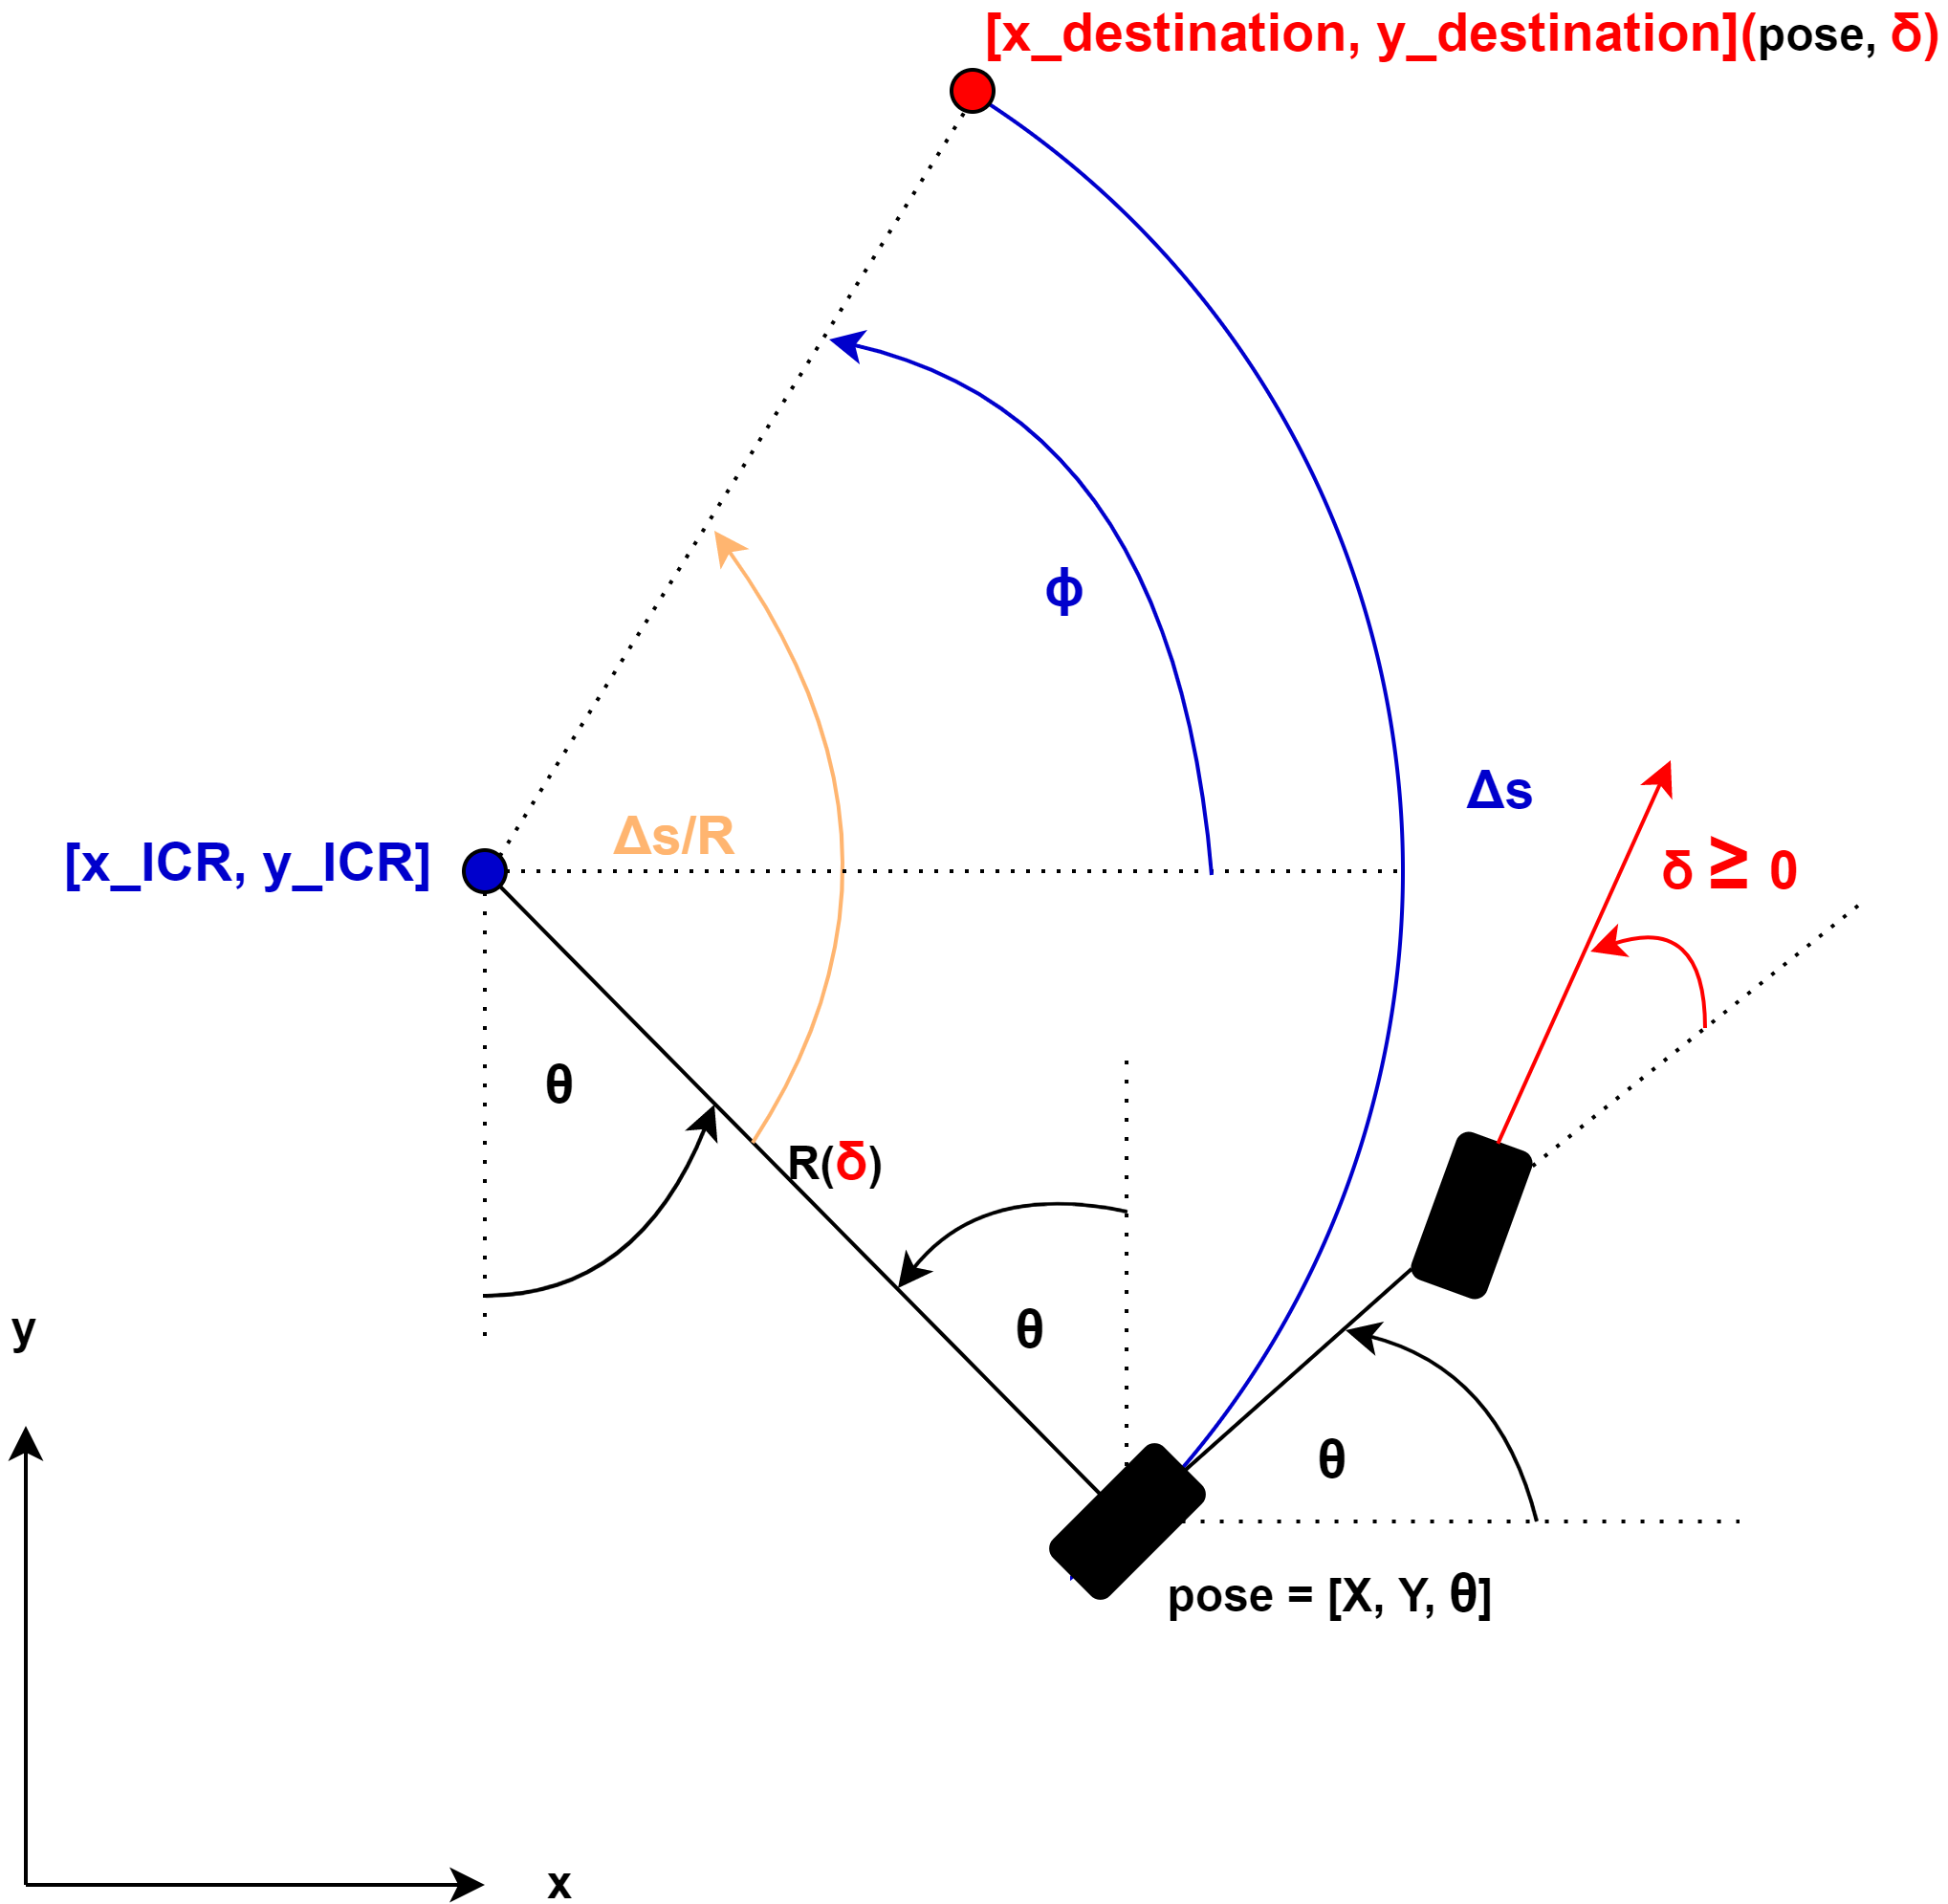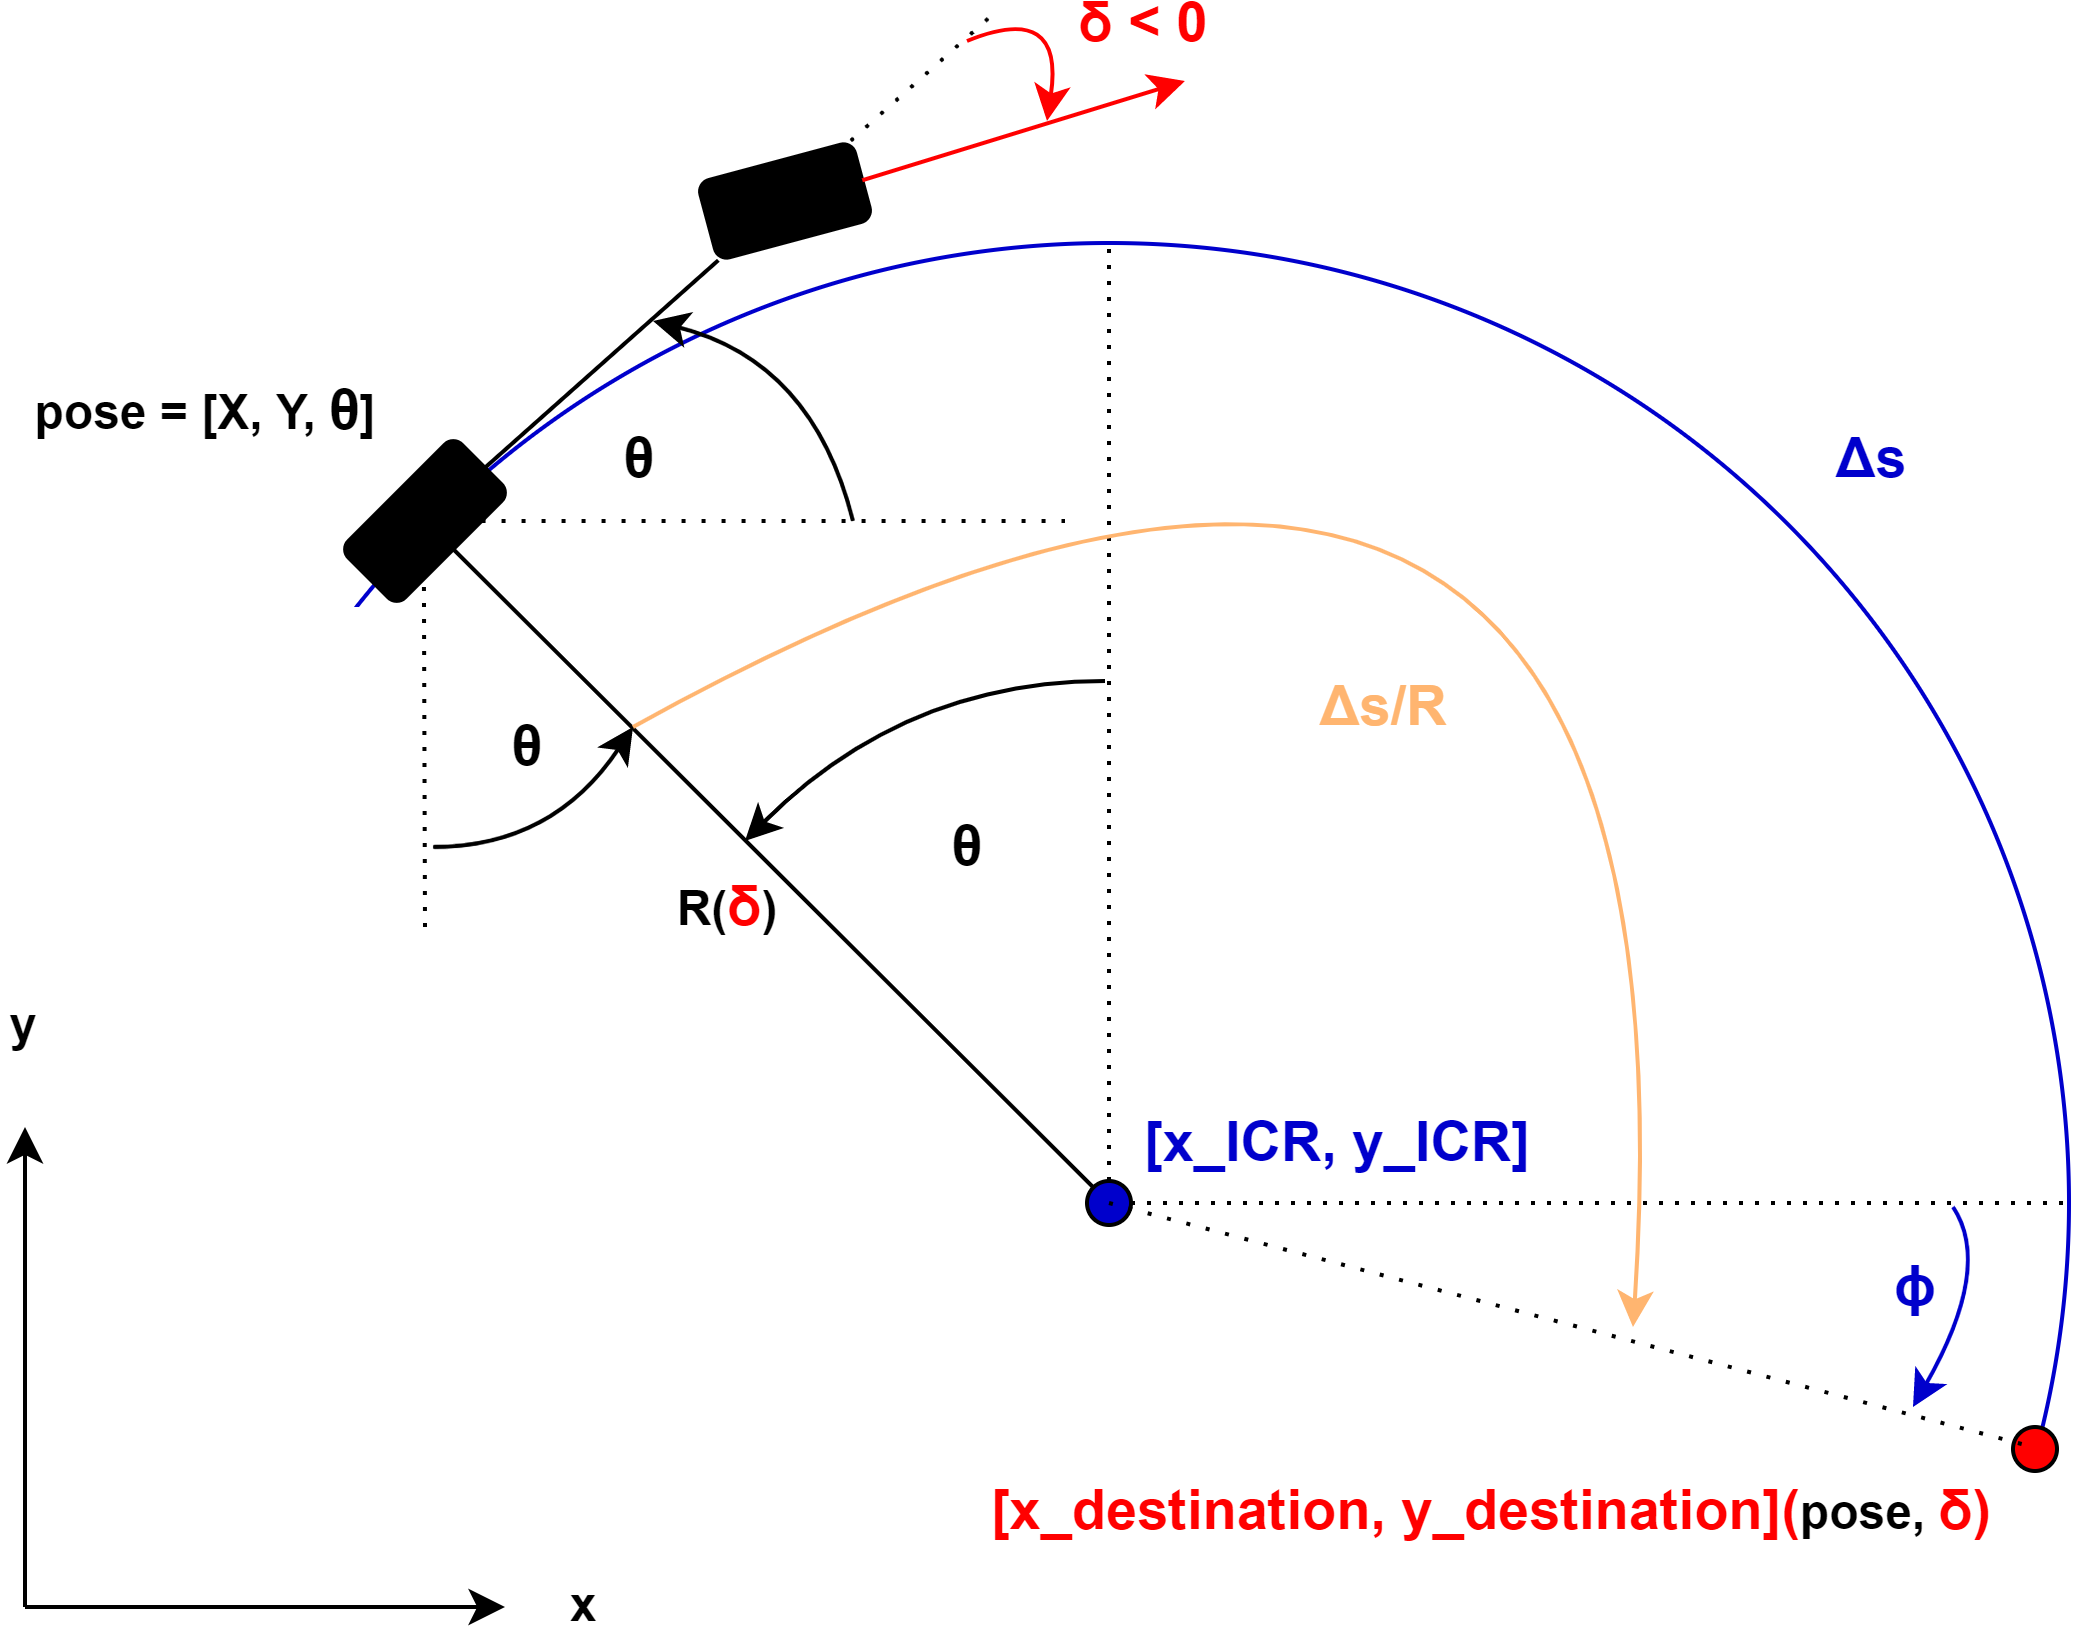

The destination point $[x_{destination}, \ y_{destination}]$ after following an arc defined by the turning radius $R(\delta)$ can be determined by using the arc's center $[x_{ICR}, \ y_{ICR}]$:


$$x_{destination} = x_{ICR} + R(\delta) cos(\phi) \\
y_{destination} = y_{ICR} + R(\delta) sin(\phi) 
$$


According to the kinematic bicycle model the turning radius is:


$$R(\delta) =
    \begin{cases}
      \frac{L}{tan(\delta)} & \text{if } \delta \geq 0 \\
      - \frac{L}{tan(\delta)} & \text{if }  \delta < 0 \\
    \end{cases} $$


$[x_{ICR}, \ y_{ICR}]$ can be expressed using the vehicle's pose $[X, \ Y, \ \theta]$:

$\delta \geq 0 \$ :


$$x_{ICR} = X - R(\delta) sin(\theta)\\
y_{ICR} = Y +  R(\delta) cos(\theta) \\

$$


$\delta < 0$:


$$x_{ICR} = X + R(\delta) sin(\theta)\\
y_{ICR} = Y -  R(\delta) cos(\theta) \\

$$


Further, $\phi$ can be determined:

$\delta \geq 0 \$ :


$$\phi = - \frac{\pi}{2} + \theta + \frac{\Delta s}{R(\delta)}$$


$\delta < 0$:


$$\phi = \frac{\pi}{2} + \theta + \frac{\Delta s}{R(\delta)}$$


$[x_{destination}, \ y_{destination}]$ can be written as:

$\delta \geq 0 \$:


$$\begin{array}{l}
x_{destination} &=& X - R(\delta) sin(\theta) + R(\delta) cos(- \frac{\pi}{2} + \theta + \frac{\Delta s}{R(\delta)}) \\
&=& X + R(\delta) (sin(\theta + \frac{\Delta s}{R(\delta)}) - sin(\theta)) 
\end{array}{} \\

\\

\begin{array}{l}
y_{destination} &=& Y +  R(\delta) cos(\theta) + R(\delta) sin(- \frac{\pi}{2} + \theta + \frac{\Delta s}{R(\delta)})  \\
&=& Y +  R(\delta) (cos(\theta) - cos(\theta + \frac{\Delta s}{R(\delta)})) 
\end{array}{}

$$


$\delta < 0$:


$$\begin{array}{l}
x_{destination} &=& X + R(\delta) sin(\theta) + R(\delta) cos(\frac{\pi}{2} + \theta + \frac{\Delta s}{R(\delta)}) \\
&=& X + R(\delta) (sin(\theta)  -  sin(\theta + \frac{\Delta s}{R(\delta)})) \\
\end{array}{} \\

\\

\begin{array}{l}
y_{destination} &=& Y -  R(\delta) cos(\theta)  + R(\delta) sin(\frac{\pi}{2} + \theta + \frac{\Delta s}{R(\delta)}) \\
&=& Y +  R(\delta) (cos(\theta + \frac{\Delta s}{R(\delta)})  - cos(\theta))
\end{array}{}



$$


The variable $cclockwise$ can be difned as: 


$$cclockwise =
    \begin{cases}
      -1 & \text{if } \delta \geq 0 \\
      1 & \text{if }  \delta < 0 \\
    \end{cases} $$


Finally:


$$x_{destination} = X - cclockwise*R(\delta) (sin(\theta + \frac{\Delta s}{R(\delta)}) - sin(\theta)) \\

y_{destination} = Y - cclockwise* R(\delta) (cos(\theta) - cos(\theta + \frac{\Delta s}{R(\delta)})) 


$$


Using this formula, the boundries of the reachability area can be determined. For the lower, upper and emergency boundary, the steering angle is varied and the arc length $\Delta s$ is kept constant. For the right and left boundary, it is the other way around:

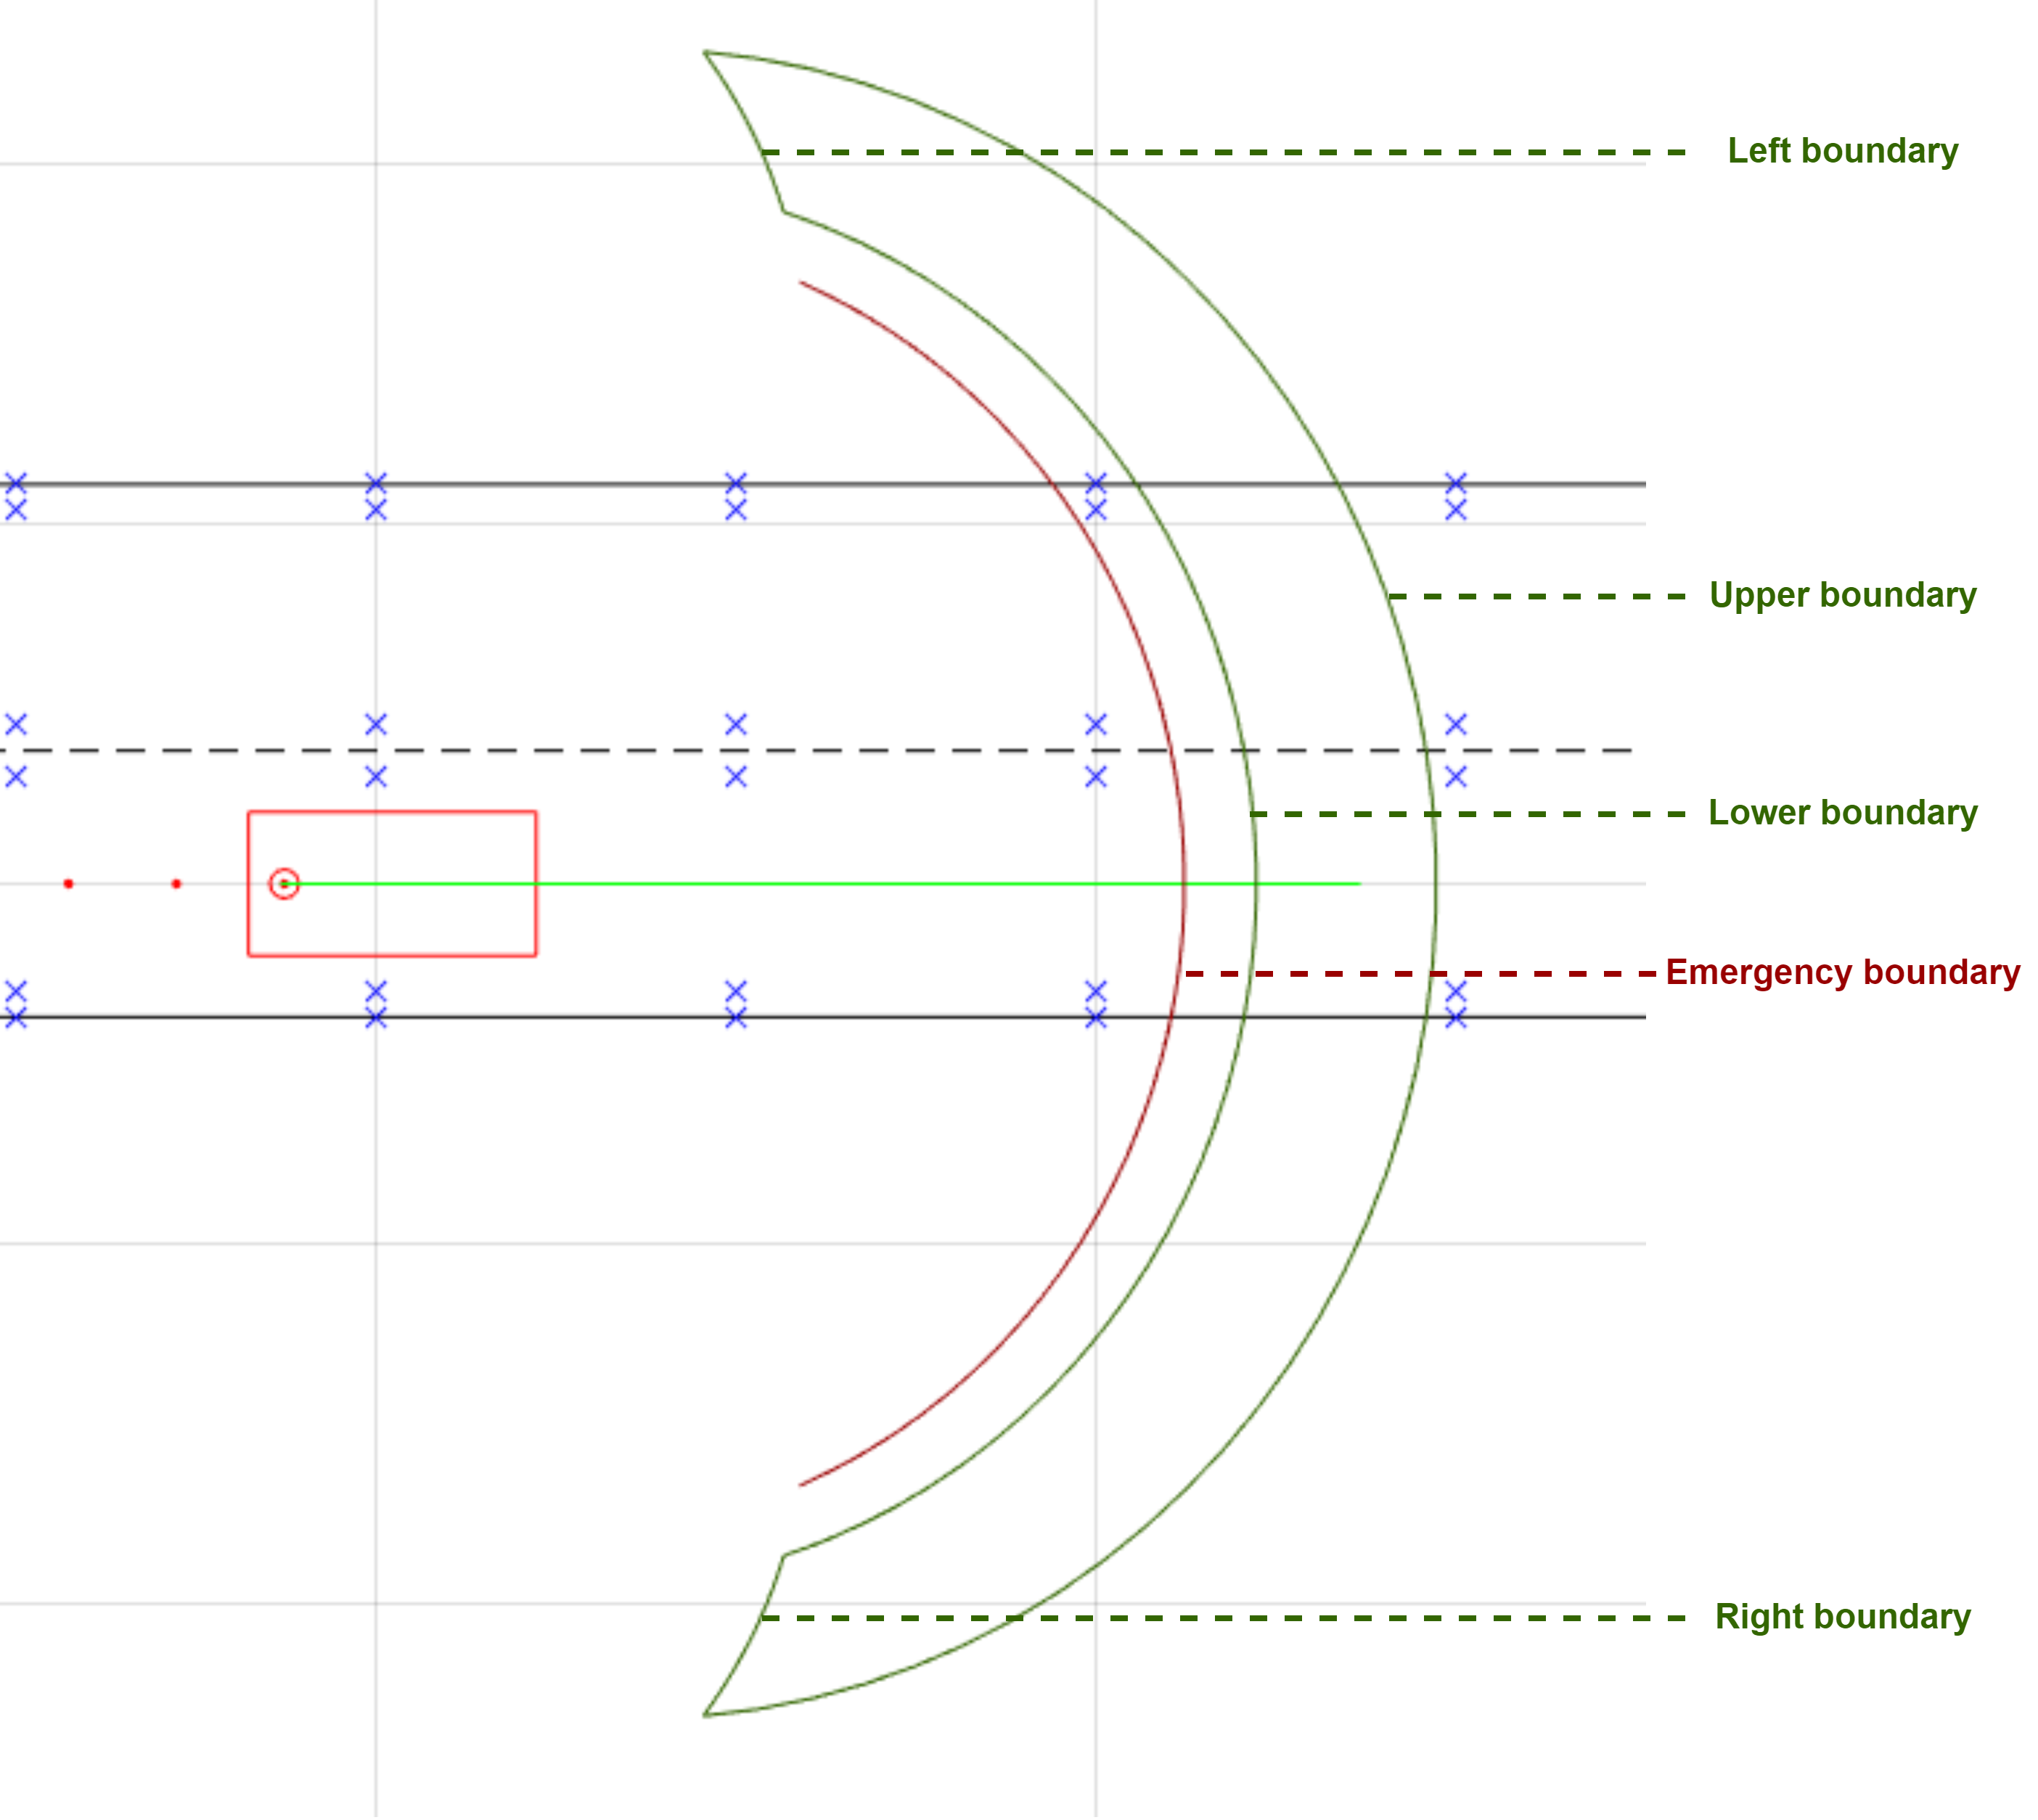


$$\begin{array}{lccc}
\text{Lower boundary} &:& a = a_{min} =  const. &,&\  -\delta_{max} \leq \delta  \leq \delta_{max}&,& \ \Delta s = s_{a_{min}}(k+1) - s(0) \\
\text{Upper boundary} &:& a =  a_{max} =  const. &,& \  -\delta_{max} \leq \delta  \leq \delta_{max}&,& \ \Delta s = s_{a_{max}}(k+1) - s(0) \\
\text{Emergency boundary} &:& a =  a_{emergency} =  const. &,& \  -\delta_{max} \leq \delta  \leq \delta_{max}&,& \ \Delta s = s_{a_{emergency}}(k+1) - s(0) \\
\text{Right boundary} &:& a_{min} \leq a \leq a_{max}&,& \ \delta = -\delta_{max} = const. &,& \ s_{a_{min}}(k+1) - s \leq \Delta s \leq  s_{a_{max}}(k+1) - s \\
\text{Left boundary} &:& a_{min} \leq a \leq a_{max}&,& \ \delta = \delta_{max} = const. &,& \ s_{a_{min}}(k+1) - s \leq \Delta s \leq  s_{a_{max}}(k+1) - s
\end{array}{}$$


To go straight, the steering angle must be zero: $\delta = 0$. This results in an infinite turning radius $R(\delta = 0) \rightarrow \infty$. Thus, the limit for the formulation can be found by using [L'Hôpital's rule](https://en.wikipedia.org/wiki/L%27H%C3%B4pital%27s_rule):


$$\begin{array}{ll}
\lim_{R\to\infty} x_{destination} - X &=& \lim_{R\to\infty} \frac{f(R)}{g(R)} &=& \lim_{R\to\infty} \frac{-cclockwise*(sin(\theta + \frac{\Delta s}{R}) - sin(\theta))}{1/R } \\
&=&  \lim_{R\to\infty} \frac{f \prime (R)}{g \prime (R)} &=& \lim_{R\to\infty} \frac{cclockwise* 1/R^2 \ \Delta s \ cos(\theta + \frac{\Delta s}{R})}{-1/R^2 } \\
&=& -cclockwise* \Delta s \ cos(\theta) 
\end{array}{} \\

\\

\Rightarrow \lim_{R\to\infty} x_{destination} = X - cclockwise* \Delta s \ cos(\theta) \\

\\

\begin{array}{ll}
\lim_{R\to\infty} y_{destination} - Y &=& \lim_{R\to\infty} \frac{f(R)}{g(R)} &=&\lim_{R\to\infty} \frac{-cclockwise*(cos(\theta) - cos(\theta + \frac{\Delta s}{R}))}{1/R } \\
&=&  \lim_{R\to\infty} \frac{f \prime (R)}{g \prime (R)} &=& \lim_{R\to\infty} \frac{cclockwise* 1/R^2  \ \Delta s \ sin(\theta + \frac{\Delta s}{R})}{-1/R^2 } \\
&=& -cclockwise* \Delta s \ sin(\theta) 
\end{array}{} \\

\\

\Rightarrow  \lim_{R\to\infty} y_{destination} = Y - cclockwise* \Delta s \ sin(\theta) \\$$


To calculate the boundary curves, the function [calculateSteeringReachability](matlab:matlab.desktop.editor.openAndGoToLine(which('ReachabilityAnalysis.m'),  getFunctionLineNr('calculateSteeringReachability'));) is used.

# Space Discretisation

Also during initialisation, the continiuous road trajectory will be divided into discrete cells ([discretiseContinuousSpace](matlab:matlab.desktop.editor.openAndGoToLine(which('VehicleFollowingInit.m'),  getFunctionLineNr('discretiseContinuousSpace'));)):

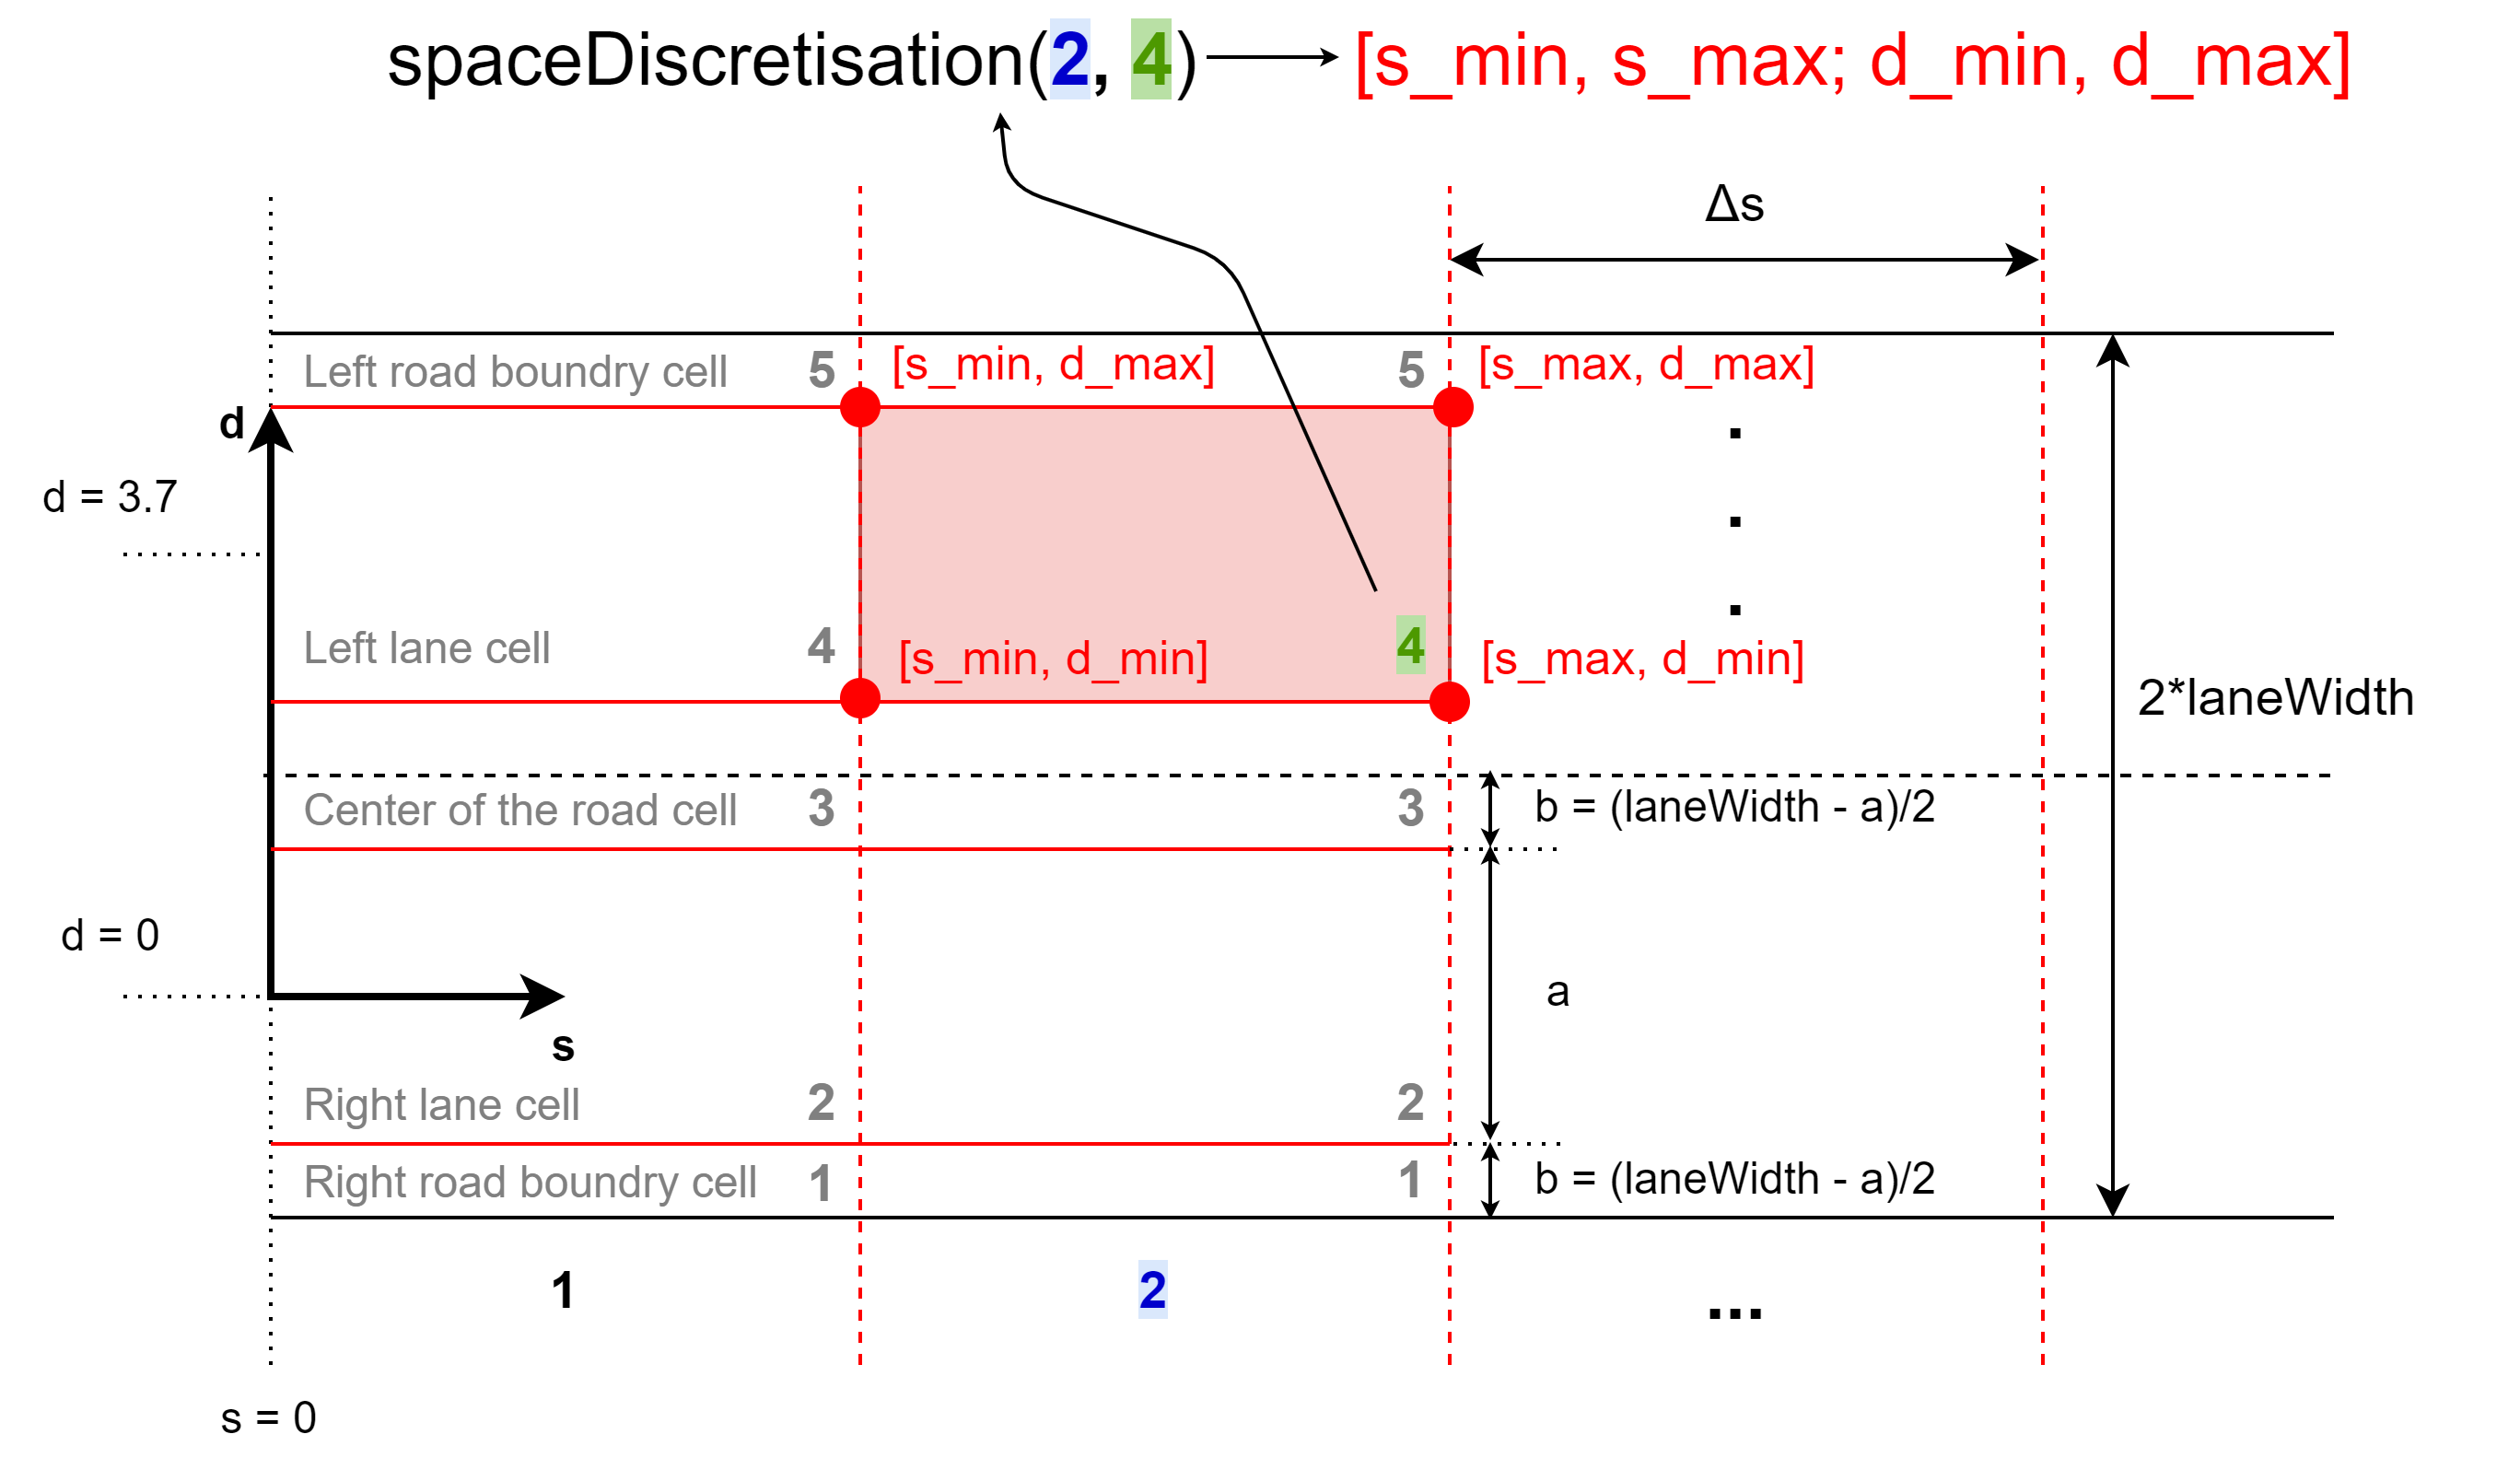

 As the figure shows, the road's length ($s$-coordinate) is divided into equal sized parts $\Delta s$. The road's width is divided into different sized parts. So for each $\Delta s$, 5 discrete cells are created:

- Right road boundry cell (1)

- Right lane cell (2)

- Center of the road cell (3)

- Left lane cell (4)

- Left road boundry cell (5)

For this, a cell_length $\Delta s$ and a laneCell_width $a$ must be specified. The width $b$ to set the width of the road boundry cells and the center of the road cell is defined as:

 
$$b = \frac{laneWidth-a}{2}$$


This follows from:


$$a + 2b = laneWidth$$


The continuous cell boundries **[s_min, s_max; d_min, d_max]** are stored in the cell array structure (they are seperately stored in the matrix structure *spaceDiscretisationMatrix *to reduce computational resources when working with the structure) *spaceDiscretisation*:

VehicleFollowingInit;
spaceDiscretisation

Because Frenet coordinates are used, the discretisation also easily works for curved roads.

## Discrete to Continuous

To get the continuous boundries **[s_min, s_max; d_min, d_max] **of a discrete cell, the function [Discrete2Continuous](matlab:open('./Vehicle Functions\Helper Functions\Discrete2Continuous.m')) can be used.

## Continuous to Discrete

To get the index of a discrete cell for a given continuous $s$ and $d$ value, the function [Continuous2Discrete](matlab:open('./Vehicle Functions\Helper Functions\Continuous2Discrete.m')) can be used.

# Decision Unit

The [decision unit](matlab:open('./Vehicle Functions\Decision.m')) selects one of the following driving modes:

- Free Drive Mode (1):

                The vehicle accelerates to and drives with the maximum desired velocity which is set to be the initial speed.

- Vehicle Following (2): 

                The vehicle adjusts its acceleration to follow the leading vehicle.

- Emergency Brake Mode (3):

                The vehicle decelerates with the maximum possible deceleration until it stops. Backward motion is not considered.

Furthermore it must be decided whether to command to:

- Follow the current trajectory (0)

- Start changing to the left lane (1)

- Start changing to the right lane (-1)

*Add more things later ...*

# Collision Detection

For [collision detection](matlab:open('./Vehicle Functions\CollisionDetection.m')) --> MOBATSim

The collision detection algorithm works by checking if any two vehicles have a geometrical intersection. As the vehicle positions, orientations and sizes are known, sizes being rectangles, the problem is reduced to checking corner points of a rectangle in the polygon of another rectangle. Since every vehicle is checked to each other, once a collision is detected, namely one or more corners of a rectangle happen to be inside another rectangle, both vehicles' collision properties are set to collide.

The checking of two rectangles with one another happens only if the vehicles are close to each other. Otherwise, it is a waste of computational resources if two rectangles are very far from each other to be checked. The threshold value for checking between vehicles that are close enough is chosen according to the L2 norm of the corner points of the rectangle, as it would not be possible otherwise for two rectangles to coincide.

**Check for Collision **- `false`** // Collided **- `false`

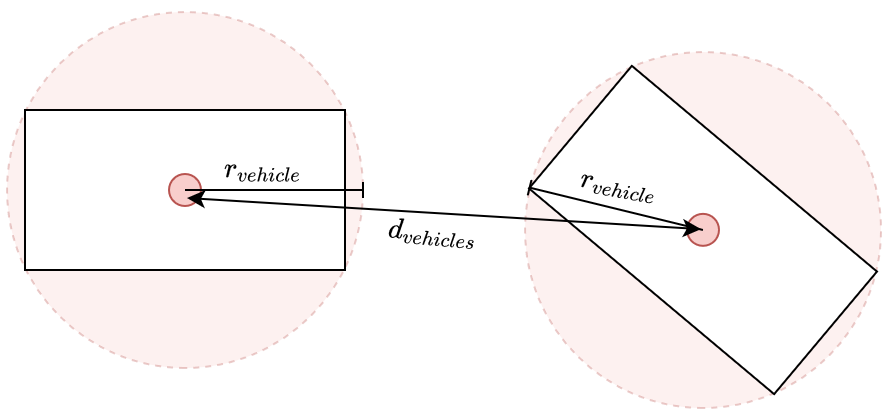

**Check for Collision **- `true`** // Collided **- `false`

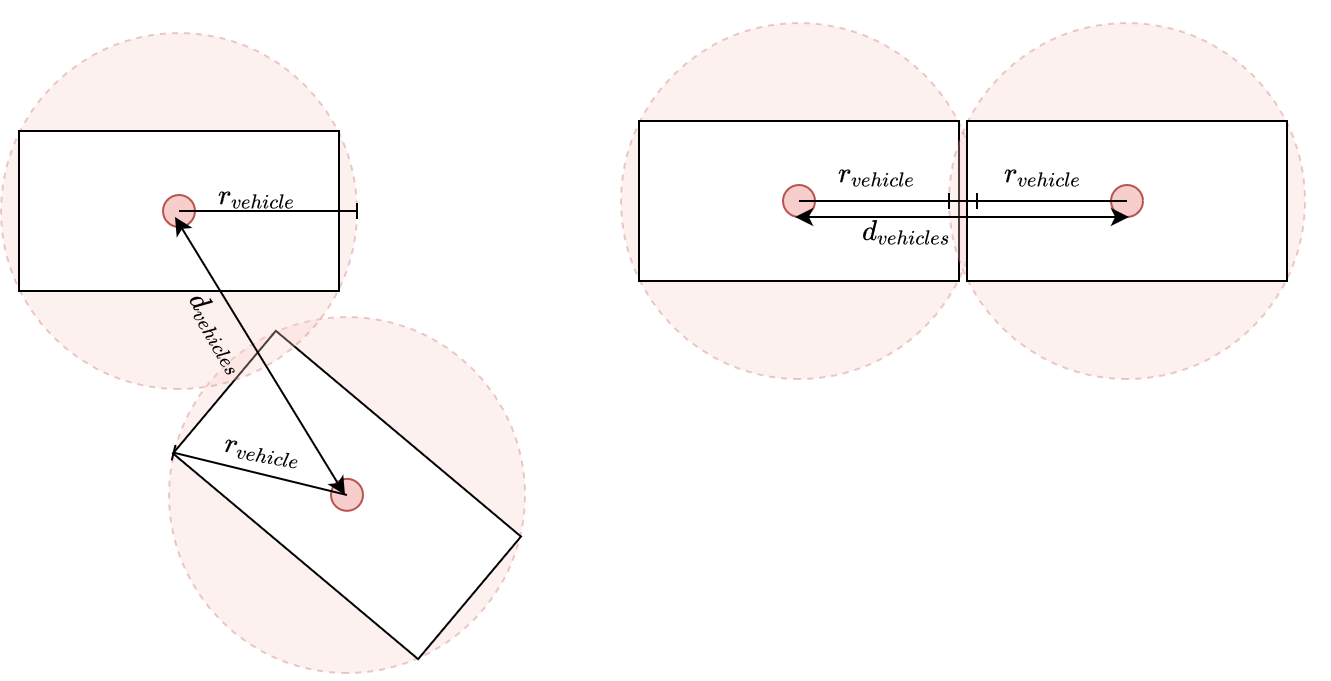

**Check for Collision **- `true`** // Collided **- true

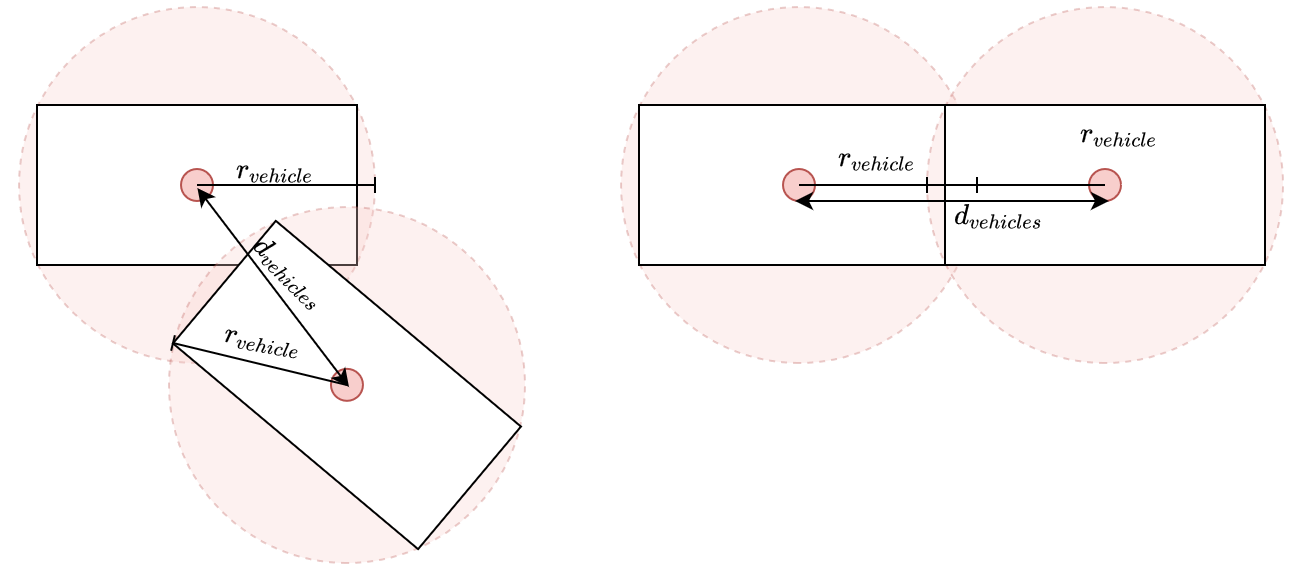

# Visualisation

For the [visualisation](matlab:open('./Visualisation\PlotDrivingScenario.m')) the MATLAB plotting function is used (alternatively a 3D animation can be used). 

When setting up the MATLAB system, first of all the road (1 in fugure)  and the space discretisation are plotted ([plotRoadLine](matlab:matlab.desktop.editor.openAndGoToLine(which('PlotDrivingScenario.m'),  getFunctionLineNr('plotRoadLine'));)) ([plotDiscreteSpace](matlab:matlab.desktop.editor.openAndGoToLine(which('PlotDrivingScenario.m'),  getFunctionLineNr('plotDiscreteSpace'));)). To represent the discrete cells, the boundries **[s_min, s_max; d_min, d_max]** are combined to draw the corner points (2) of each cell.

The procedure at every sample time step is as follows:

In the beginning, previous plots, that are not relevant anymore are deleted ([deletePreviousPlots](matlab:matlab.desktop.editor.openAndGoToLine(which('PlotDrivingScenario.m'),  getFunctionLineNr('deletePreviousPlots'));)). Then the vehicles and additional information are drawn. This includes:

- The ego (3a) and leading (3b) vehicle themselves ([plotVehicle](matlab:matlab.desktop.editor.openAndGoToLine(which('PlotDrivingScenario.m'),  getFunctionLineNr('plotVehicle'));)): To create the rectangle vehicle representation ([createRectangleVehicle](matlab:open('./Vehicle Functions\Helper Functions\createRectangleVehicle.m'))), the center of the vehicle has to be determined ([getVehicleCenterPoint](matlab:open('./Vehicle Functions\Helper Functions\getVehicleCenterPoint.m'))) because the vehicle's pose and body coordinate origin is according to the kinematic bicycle model (the center of the rear axle, which is represeted as a dot. This includes also the future predictions (4) for the leading vehicle according to the longitudinal reachability analysis. More vehicles can easily be added to be plot for visualisation.

- The vehicles' past poses (5) which results in a dotted line (traces).

- The planned trajectory (6) for the next few seconds (according to specified time horizon); For Pure Pursuit, also the next planned waypoints (7) are visualised.

- The ego vehicle's steering reachability (8)